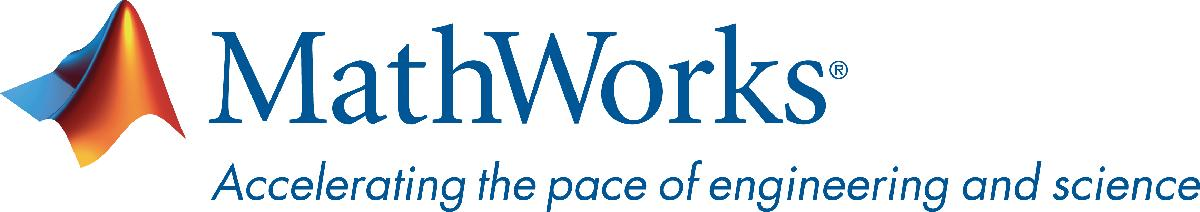

# System Composer Introduction Workshop

Using System Composer to generate a system architecture from a set of requirements.

## Abstract

This case-study involves taking a set of predefined requirements for a medical device (Ventilator & Humidication system) and modifying and linking them to a new system architecture in System Composer. Various features of System Composer will be explored ranging from requirements decomposition to trade study analysis, implementation in Simulink, and reporting. The methodology used by this workshop is Requirements, Functional, Logical, Physical (RFLP) but System Composer can support many different methodologies through the use of profiles and stereotypes.

## *1.0 Requirements Definition*

- Copy requirement definition files to the Working directory or press [**Do it for Me!**](matlab:cp = currentProject; cd(cp.RootFolder); status = rmdir('Working','s');mkdir 'Working'; copyfile("RequirementDefinition/","Working");cd Working/;)

- Lanch the Requirement Toolbox Editor:

            [**Click to Lanch Editor**](matlab:slreq.editor)

slreq.editor

    Note: The requirements editor can also be launched through the System Composer GUI.

- Open **Working/StakeholderRequirement.slreqx** in the requirements editor. These are the customer requirements.

            [Do it for Me!](matlab:slreq.clear; slreq.open('Working/StakeholderRequirement.slreqx');)

### 1.1 Import Requirements

We will import system requirements from an JAMA exported .reqif file.

Import the requirements set **Working\VentilatorRequirements_Jama.reqif**

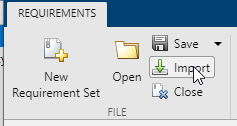

Please save set @ Working directory. Also make sure "Allow updates from external source" is turned ON.

You should now have all of the requirements imported from the Reqif file. If you select a requirement, you will see all the properties of that requirement, including custom attributes, in the property inspector on the right-hand side. 

Please make sure "Allow updates from external source" is turned ON.

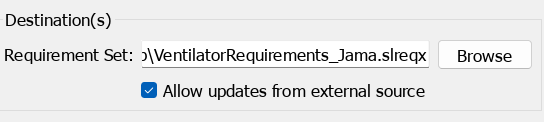

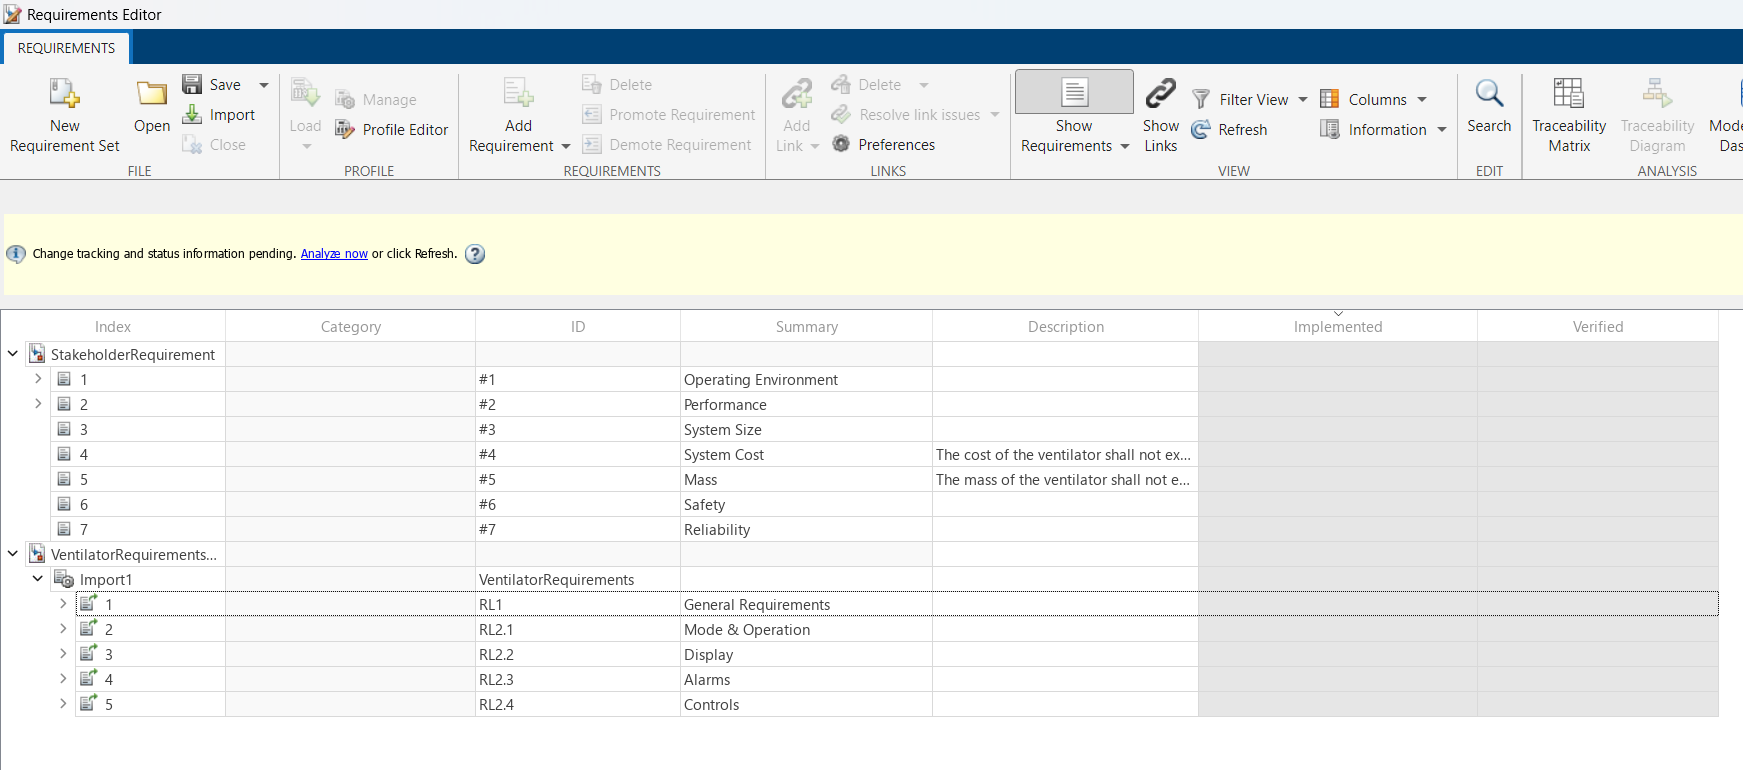

### **1.2 Adding a Requirement or updating requirement sets**

1). This section shows how one can use requirement toolbox to author and manage requirements. We will add child requirement under existing 'StakeholderRequirement' set. 

 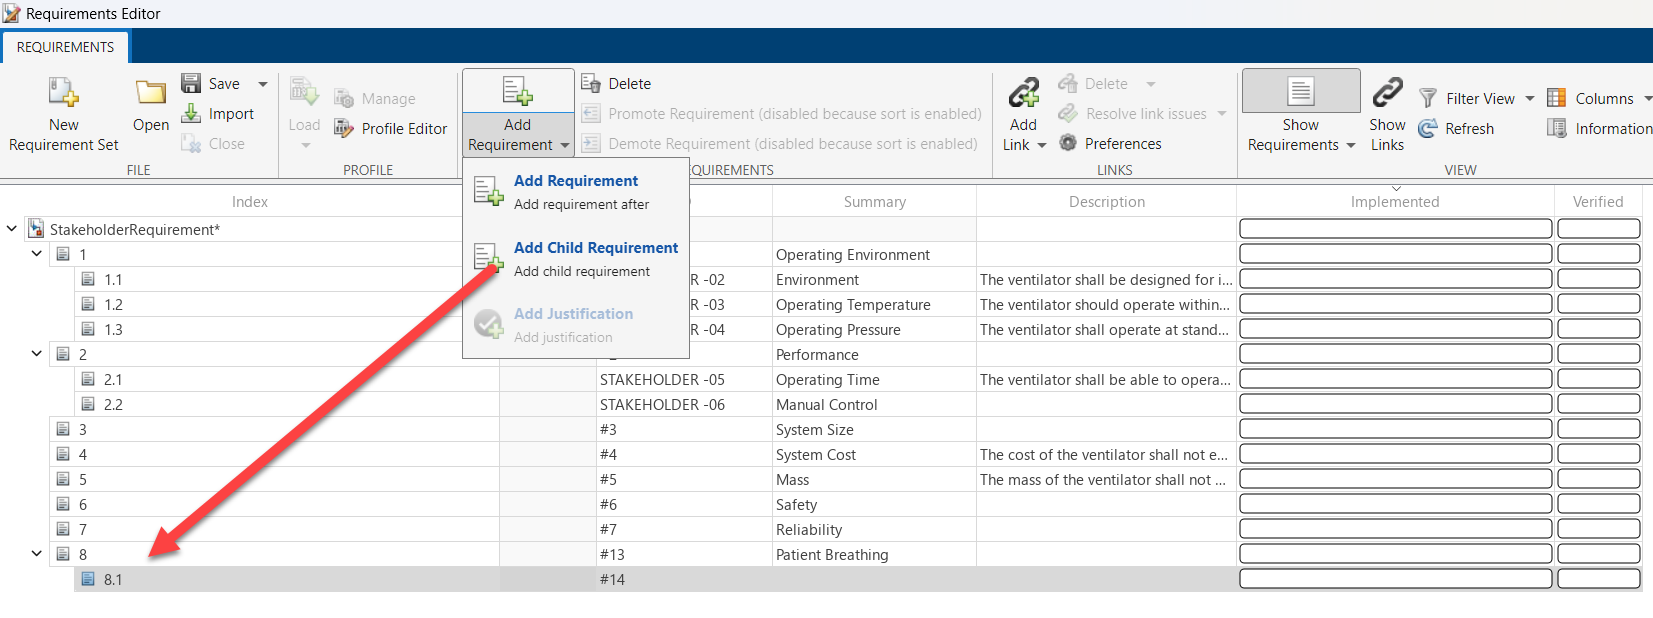

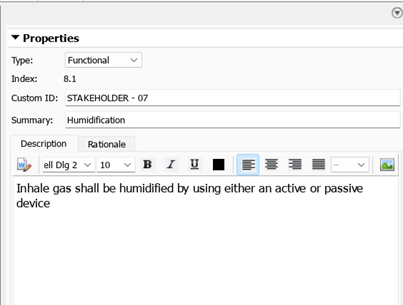

2). Turn Req 8 (Patient Breathing) type from Function to Container since now it contains few functional requirements within it.

 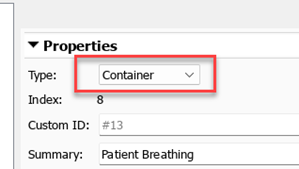

3). Update requirement after re-importing “VentilatorRequirements_Jama” requirement set. 

**What observation do you have?**  

### **1.3 Linking Requirements**

1. Click the STAKEHOLDER -07 requirement from StakeholderRequirement set.

 

2. Right click an “Select for linking with Requirement”

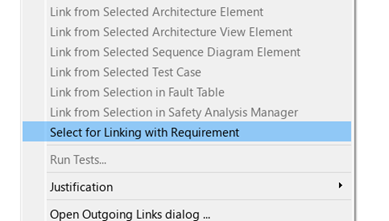

3. From VentilatorRequirements_Jama set, select RL2.1.10 requirement and "Create a link from STAKE….: Humidifcation…." as shown below 

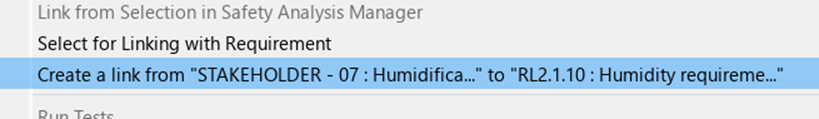 

4. After linking is complete, select the Links view at the top of the requirement editor:

 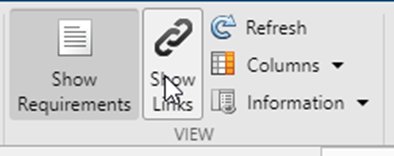

5. You should now be able to see the linkset and link that were created. Link type can also be changed from this view. The default is "Related to".

 

Links also show up in the bottom-right of the requirements view when you select a requirement that contains links.

 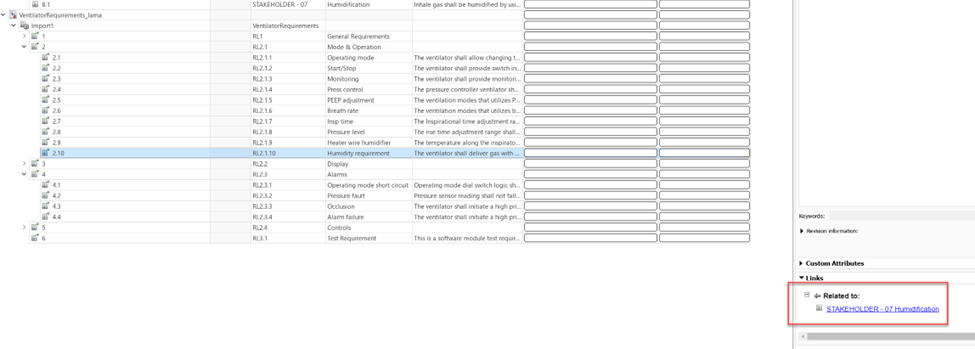

6. Use the Save All button to save the requirement set and the new linkset.

 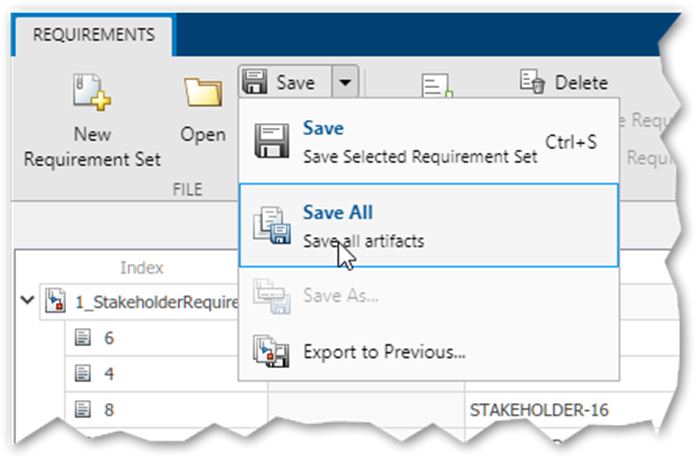

## *2.0 Architecture Creation*

### 2.1 Functional Architecture

With a set of system requirements established, we can start fleshing out the functional architecture. The functional architecture breaks down the actions or verbs that a system must perform to accomplish its goal. System Composer can be use to capture these functions, group them, decompose complex functions, and allocate them to the other architectures.

1). Copy architecture diagram and requirement set to the Working directory or press [**Do it for Me!**](matlab:cp = currentProject;  cd(cp.RootFolder); status = rmdir('Working','s');mkdir 'Working';copyfile("ArchitectureDiag/FunctionalArchitecture/StakeholderRequirement_Func.slreqx","Working");cd Working/;)

2). Launch a blank System Composer Architecture Diagram from the Home tab of the ribbon in MATLAB or by typing "systemcomposer" in the command window and pressing enter. [**Do it for Me!**](matlab:systemcomposer)

 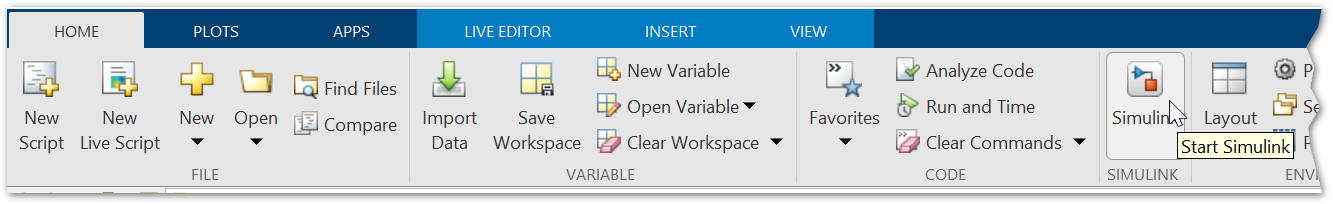

3). Expand the System Composer tree and select Create Model by clicking on the Architecture Model button.

Other architecture templates available but not covered today:

Software Architectures

[https://www.mathworks.com/help/systemcomposer/author-simulate-deploy-software-architectures.html](https://www.mathworks.com/help/systemcomposer/author-simulate-deploy-software-architectures.html)

 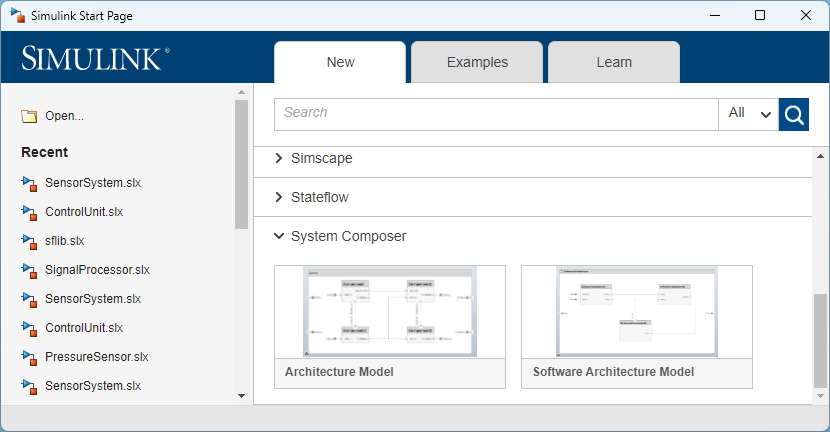

4). Double-Click "untitled" on the top-left of the canvas and change the name to Functional_Ventilation.

 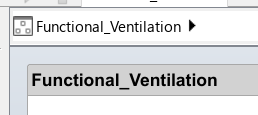

 5). Click and drag on the canvas to make a box.

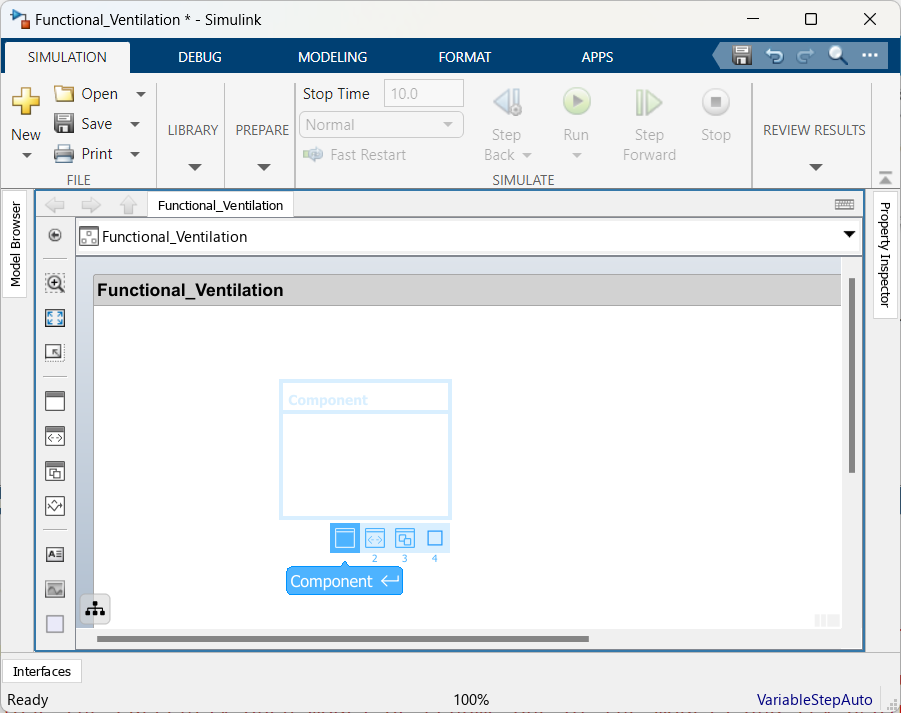

6). Select "Component" to create a new component and name it "Setting Up Ventilation"

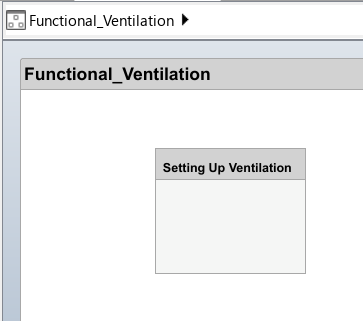

7). Add components for the following additional items:  

- Humidifier Setup

- Ventilation Connection to Patient

- Monitoring & Safety Checks

#### 2.1.1 Child Architecture

1). Open the architecture of the "Setting Up Ventilation" component by double-clicking it.

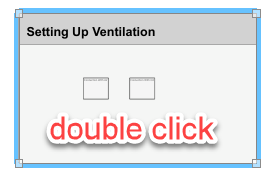

2). Add two child components, "Connection with Air" and "Connection with O2".

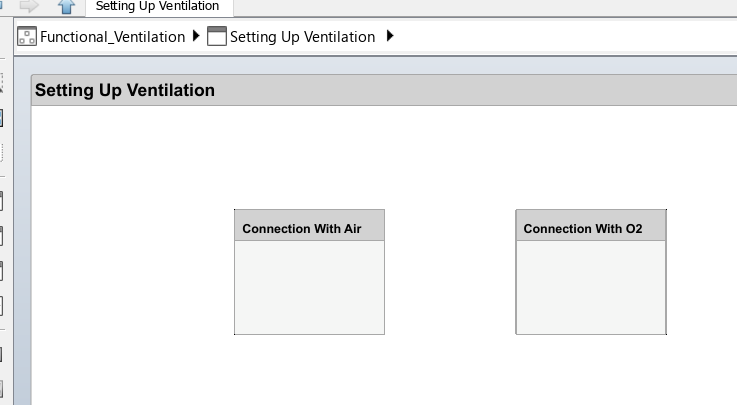

3). Press the save button. 

[**Do it for Me!**](matlab:run('FunctionalArch_Complete.m'))** -- **This will be our functional architecture. Depending on your workflow, you may decide to add more detail by further decomposing complex functions or connecting functions to create a functional flow block diagram.

#### 2.1.2 Requirements Linking to Architecture Models

Now that our functional architecture has been defined, lets create traceability from our system requirements to our architecture. Requirements can be linked directly to System Composer components and ports.

1). In the FunctionalArchitecture diagram, select the Apps tab in the ribbon and then Requirements Manager.

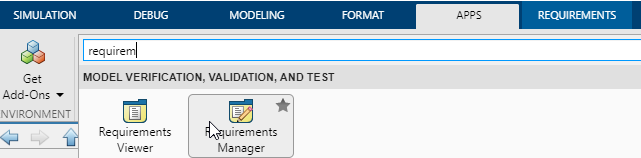

2). In the requirements manager, open StakeholderRequirement_Func.slreqx which was reviewed and edited earlier in this workshop.

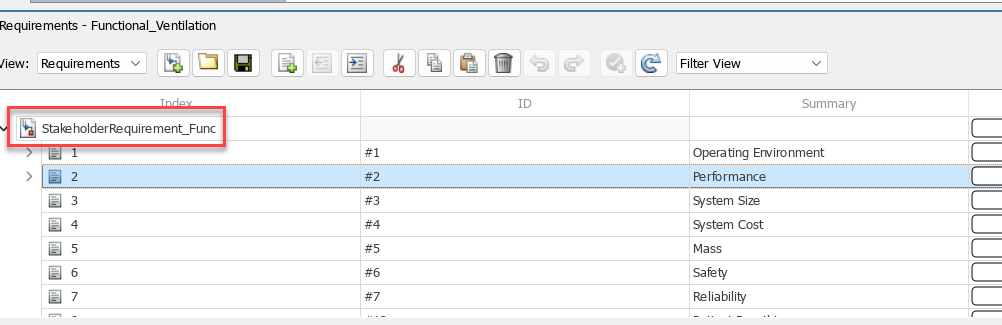

3). Click-and-drag previously added "humidification"  (STAKEHOLDER - 07) requirement to "Humidifier Setup" functional component.

4). Observe the requirements icon has been added in the top-right corner to show that the component has a linked requirement.

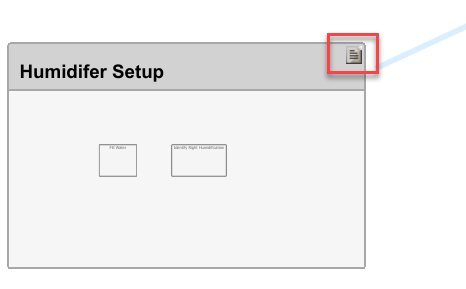

5). Click the requirements icon and select "Show".

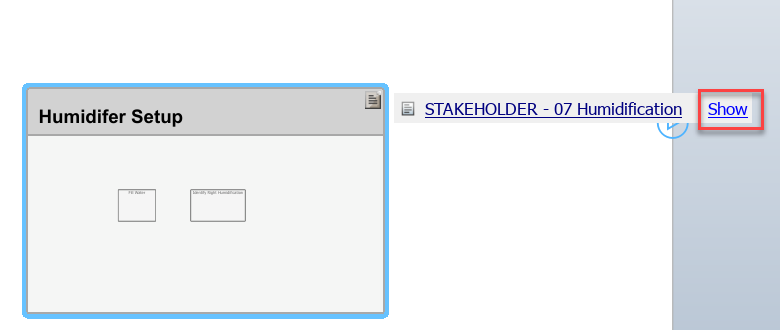

6). You will see 'implemented' status change to 'blue' and link being established for that humidification requirement.

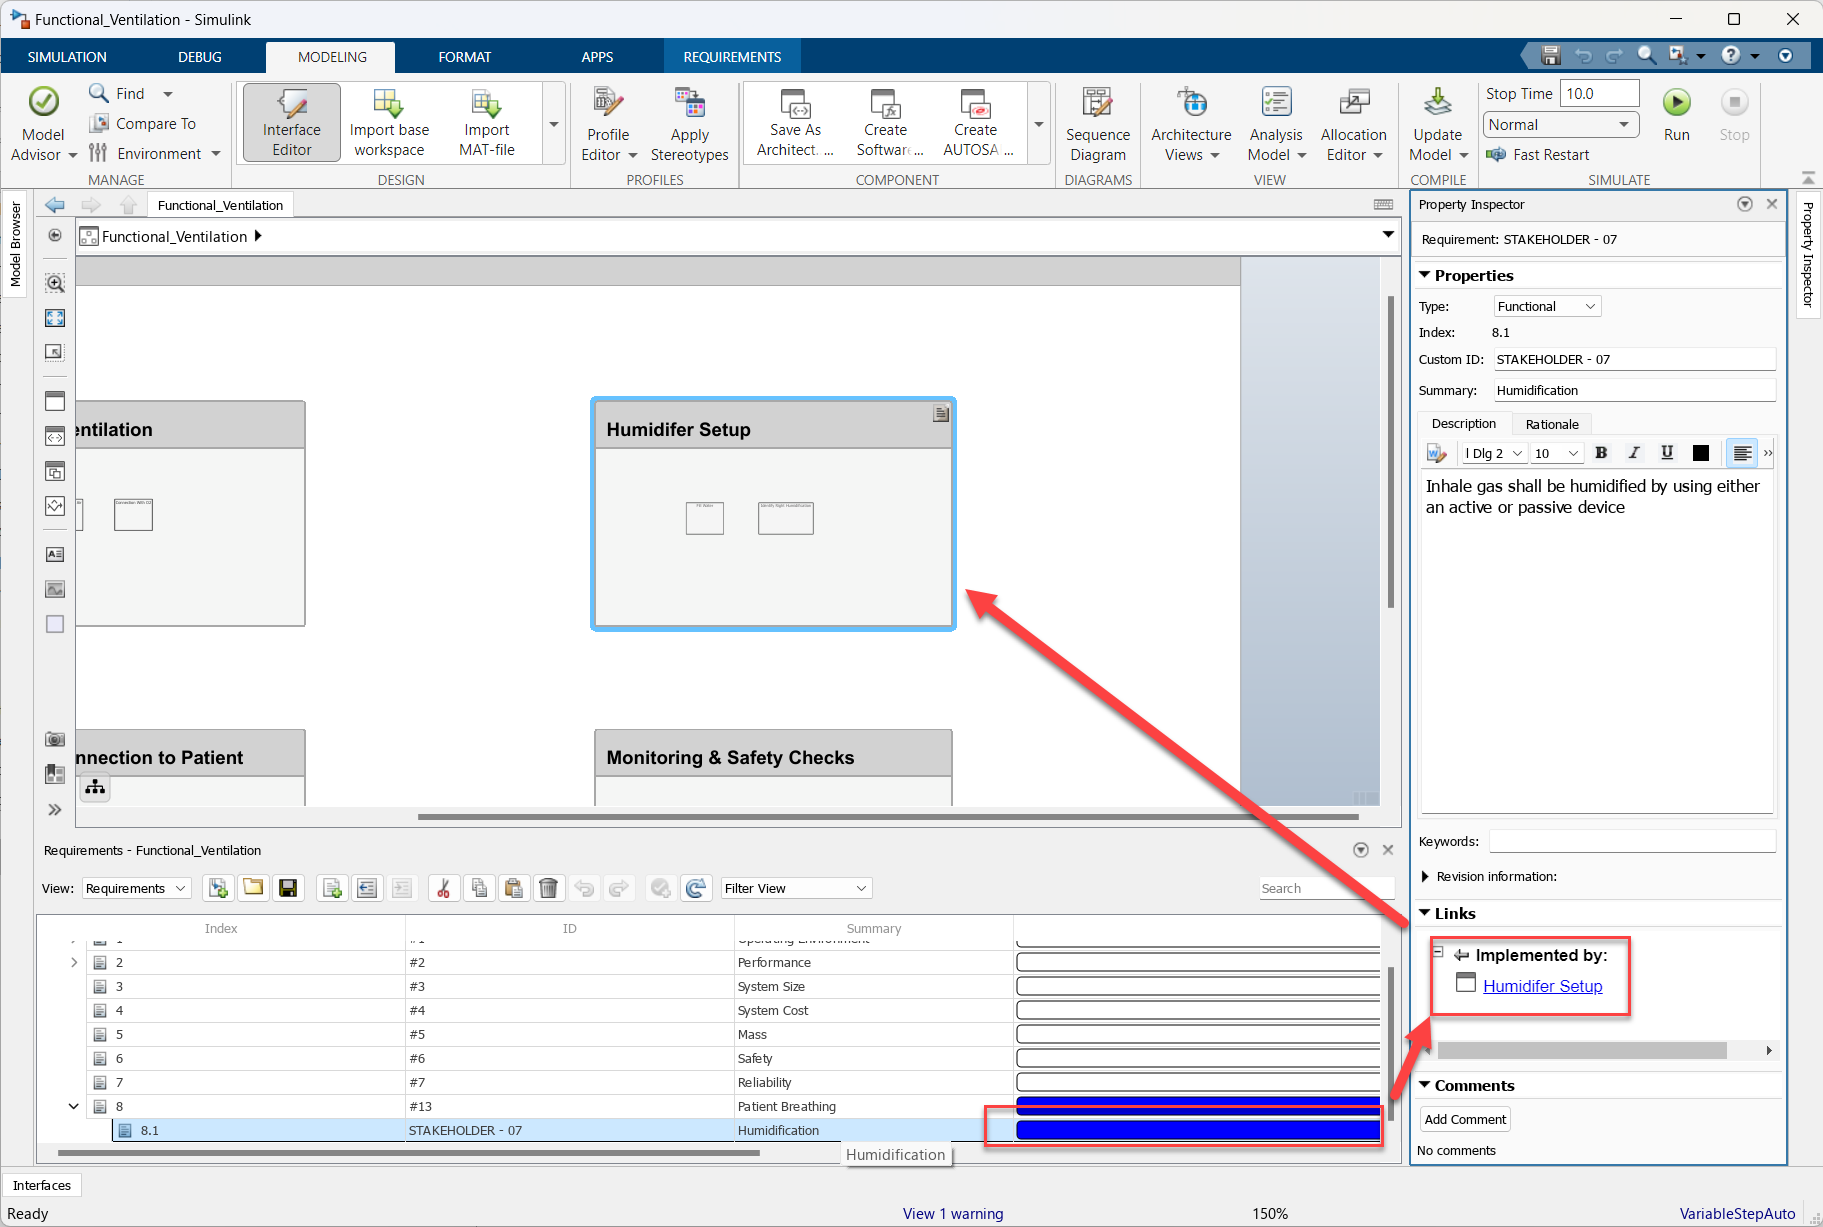

#### 2.1.3 Traceability Diagram

The traceability diagram shows you upward and downward traceability of a requirement.

1). Right-click the "humidification"  (STAKEHOLDER - 07) requirement in the requirement editor or requirement manager and select "View Traceability Diagram".

2).  In the System Composer property inspector, change the description of STAKEHOLDER - 07 to something like this:--> "Condensation should be less than 25mL." (make sure add any value or change existing value in order to see impact on traceability). 

 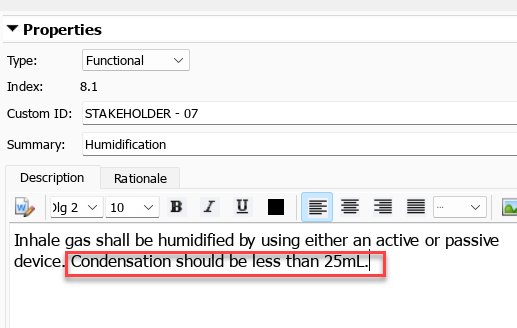

and save the requirements set

3). Press the "Analyze" button in the traceability diagram.

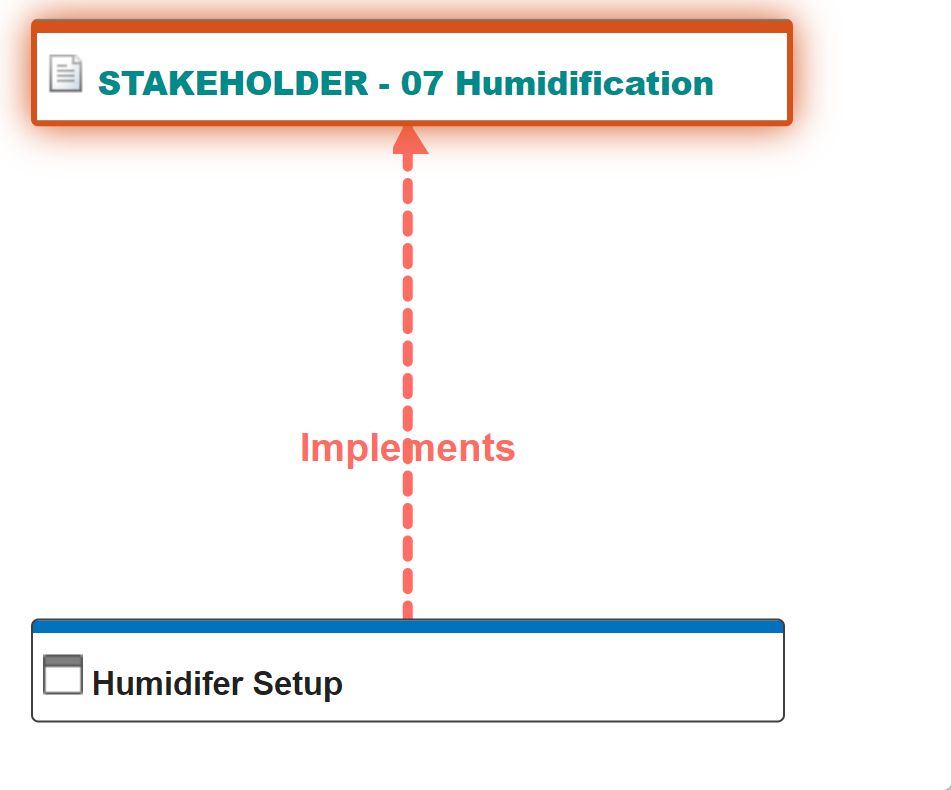

4). Right-click on the link and choose "Navigate to: Link" 

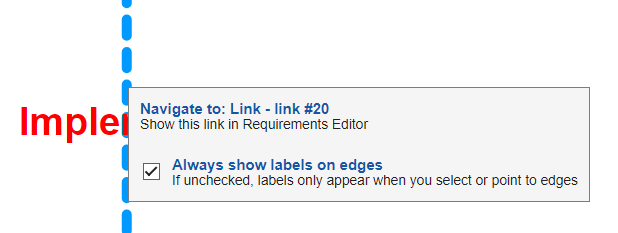

5). The suspect link can be cleared from the requirements editor by right-clicking it and selecting "Clear Issue".

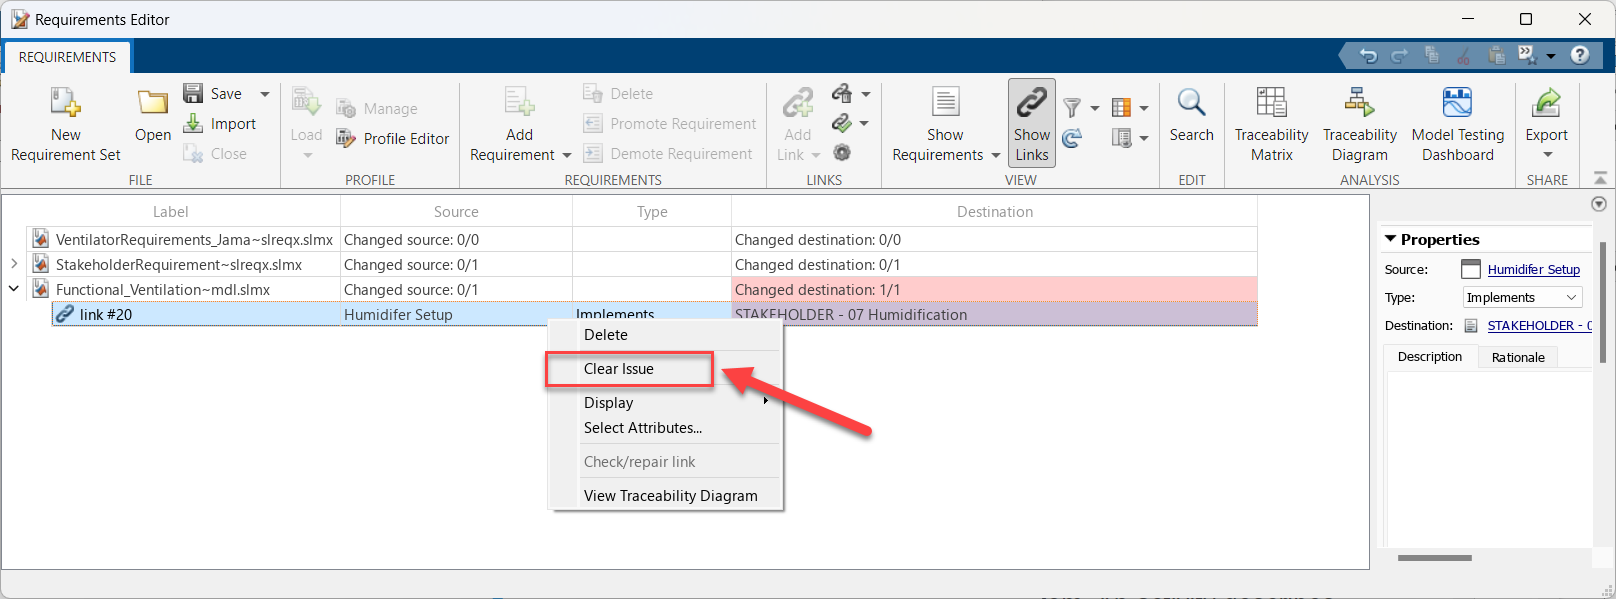

6). Enter a comment and press Clear Issue.

 Enter a comment and press Clear Issue.

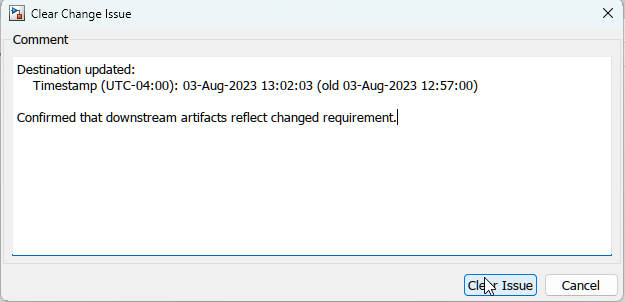

7). Save Selected Link Set and close the traceability diagram.

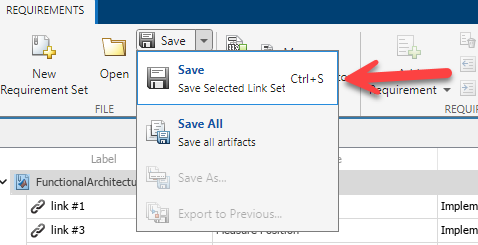

Final functional architecture model and linked requirement looks like this --> [**Copy all files from folder!**](matlab:cp = currentProject;  cd(cp.RootFolder); status = rmdir('Working','s');mkdir 'Working';copyfile("ArchitectureDiag/FunctionalArchitecture/","Working");cd Working/;)

### 2.2 Logical Architecture

The logical architecture is used to group the functions according to a certain set of logical subsystems. Multiple logical architectures may be designed to test different function allocations. The logical architecture can represent things such as partitioned applications or other groupings of functions intended to operate as a single unit. The logical architecture can then be decomposed further into subsystem architectures, software architectures, or linked directly to behavioral models that will be used for code generation and simulation. In this exercise, we will learn how to use the co-authoring workflow of the sequence diagram to build our logical architecture.

Copy files from **ArchitectureDiag/LogicalArchitecture** folder to the **Working** directory or press[** it for Me!**](matlab:cp = currentProject;  cd(cp.RootFolder); status = rmdir('Working','s');mkdir 'Working';copyfile("ArchitectureDiag/LogicalArchitecture/","Working");cd Working/;)

#### 2.2.1 Create Logical Architecture

1). We learned creating architecture model from scratch during previous sessions. In this module, we will use existing architecture model and add few logical behavior of the humidifier logic. Open "HumidifierController.slx" model. [**Do it for Me!**](matlab:open_system(cp.RootFolder + '/Working/HumidifierController_Start.slx');) 

2). Create below components 

- Humid Control

- Heater Control

3). Connect all interfaces from 'SupervisoryLogic' as shown below

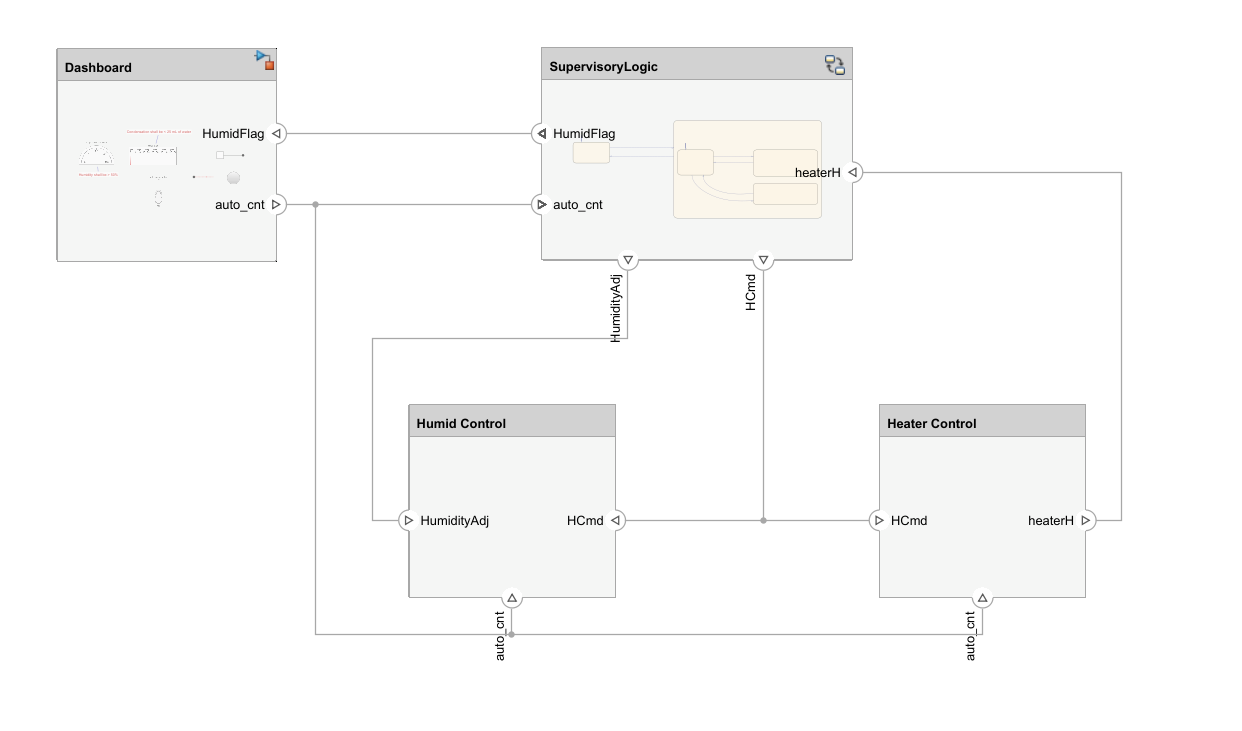

4). Left-click and drag from the right edge of the Humid Control component to the left edge of the Heater Control component to add two more connections and name those as 'HumidH' and 'Thermistor'.  

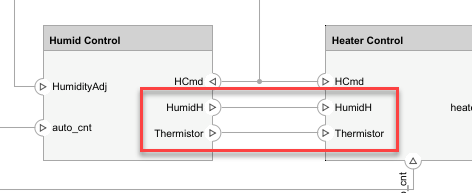

#### 2.2.2 Interfaces

The interface editor in System Composer can be used to create and assign interfaces. Interfaces can be used to define the structure and type of data that will be traveling in and out of the ports. There are four types of interfaces in System Composer.

- Composite Data Interface - A structured interface with multiple elements (such as a bus or message) that supports nesting

- Value Type interfaces for scalar or homogenous data (such as a single signal or array)

- Physical Interface - A structured interface of Simscape physical signals such as mechanical, electrical, and hydraulic (this interface is only found in the generic template)

- Client-Server Interface - A call/response interface specific to function calls in software architectures (this interface is only found in the software architecture template)

Interfaces can be shared or owned. Shared interfaces are defined in the data dictionary and can be used to type multiple ports across components, architectures, and even Simulink models. Owned interfaces are defined directly on the port and cannot be reused by other components and ports (better for one-off interface definition).

For this workshop, we will just be using shared Value Type interfaces.

1). Open the [Logical Architecture](matlab:open_system('HumidifierController_Start');) in System Composer and open the interface editor from the DESIGN section of the Modeling tab (the interface editor might already be opened but collapsed at the bottom of System Composer).

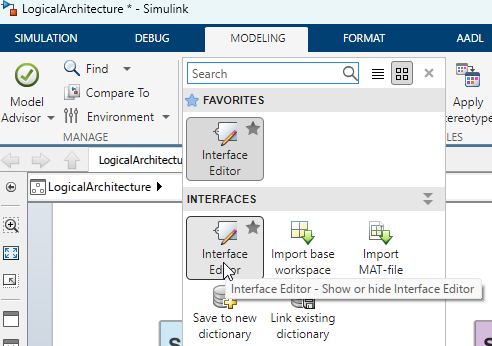

2). One can create new interfaces and convert that into Data Dictionary.. However, for this workshop, we will be using existing one located into "Data" directory within a project.

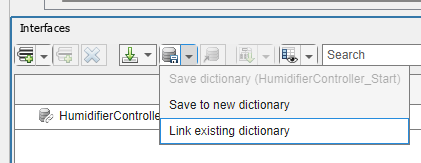

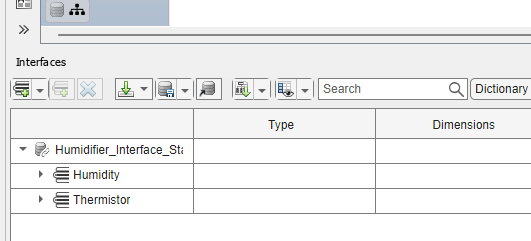

3). Add new interface called it as 'Command'.. Add two signals 1. Humidity with type double and 2. Heater with type double into Command interface bus.

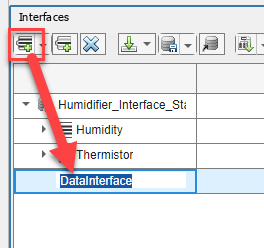

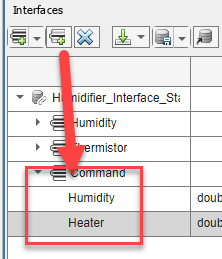

4). There are three ways to assign interfaces. Let's try one! Select Command interface then right click on HCmd port on Heater Control or Humid Control block and select "Assign to Selected Port(s)". 

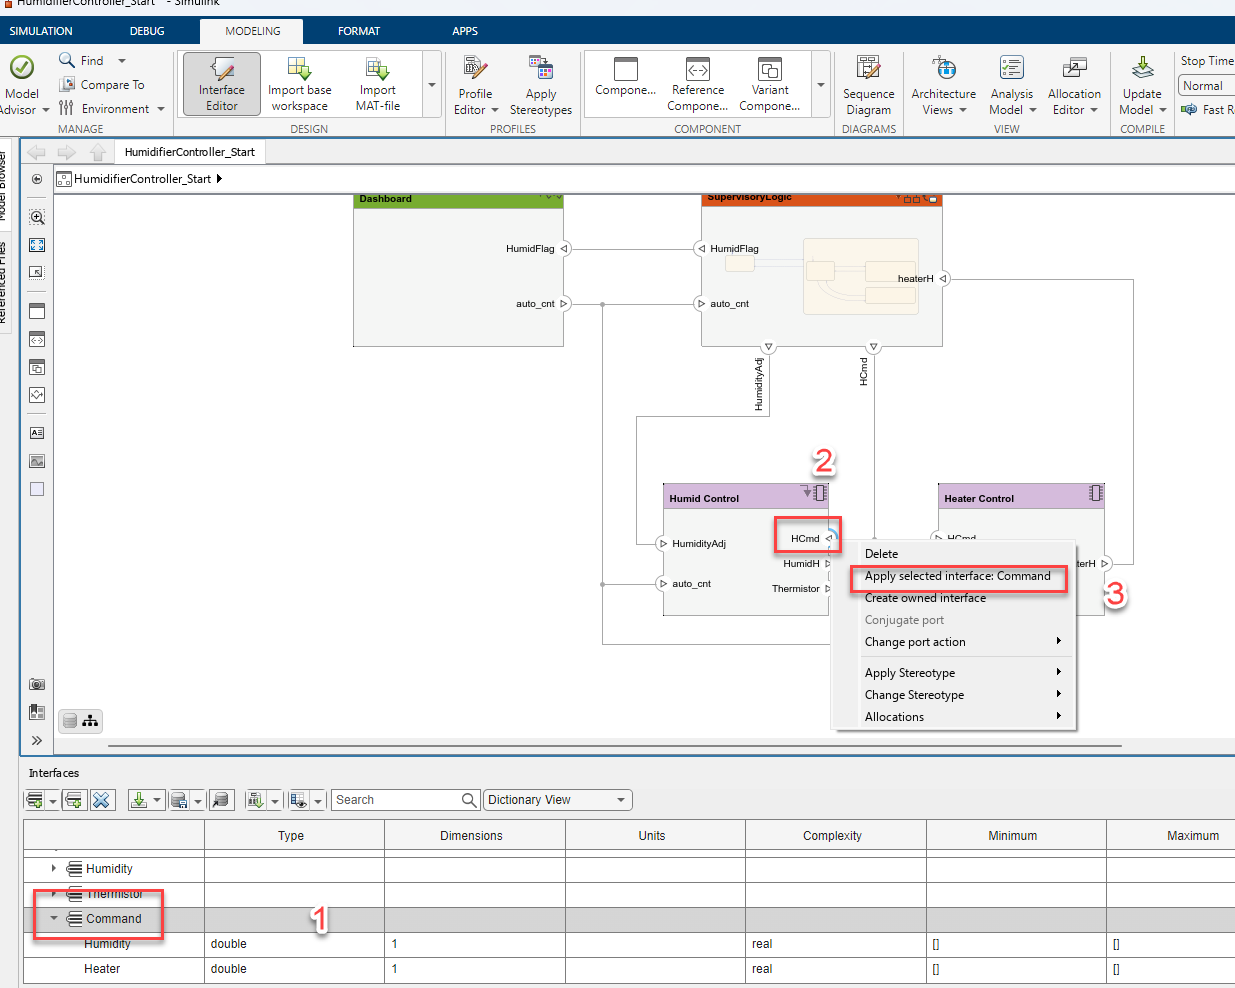

5). Similiary, assign Humidity interface to HumidH and HeaterH ports from Humid and Heater Control blocks respectively.  

6). Also apply Thermistor interface to Thermistor port of the Humid Control component. 

7). Update the model and make sure no error exist and interfaces are assigned appropriately. 

8). One can apply stereotypes on interface as well as described previously. If you want to apply stereotype "Air" onto humidity interface. First 'manage' and imported profile as show below. 

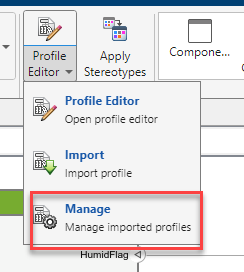

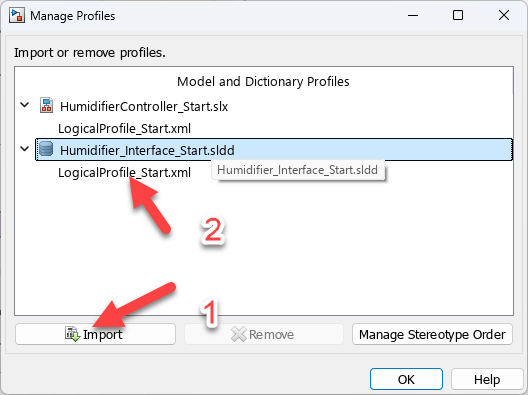

9). Select Humidity interface and from property inspector, select "Air" stereotype as shown below

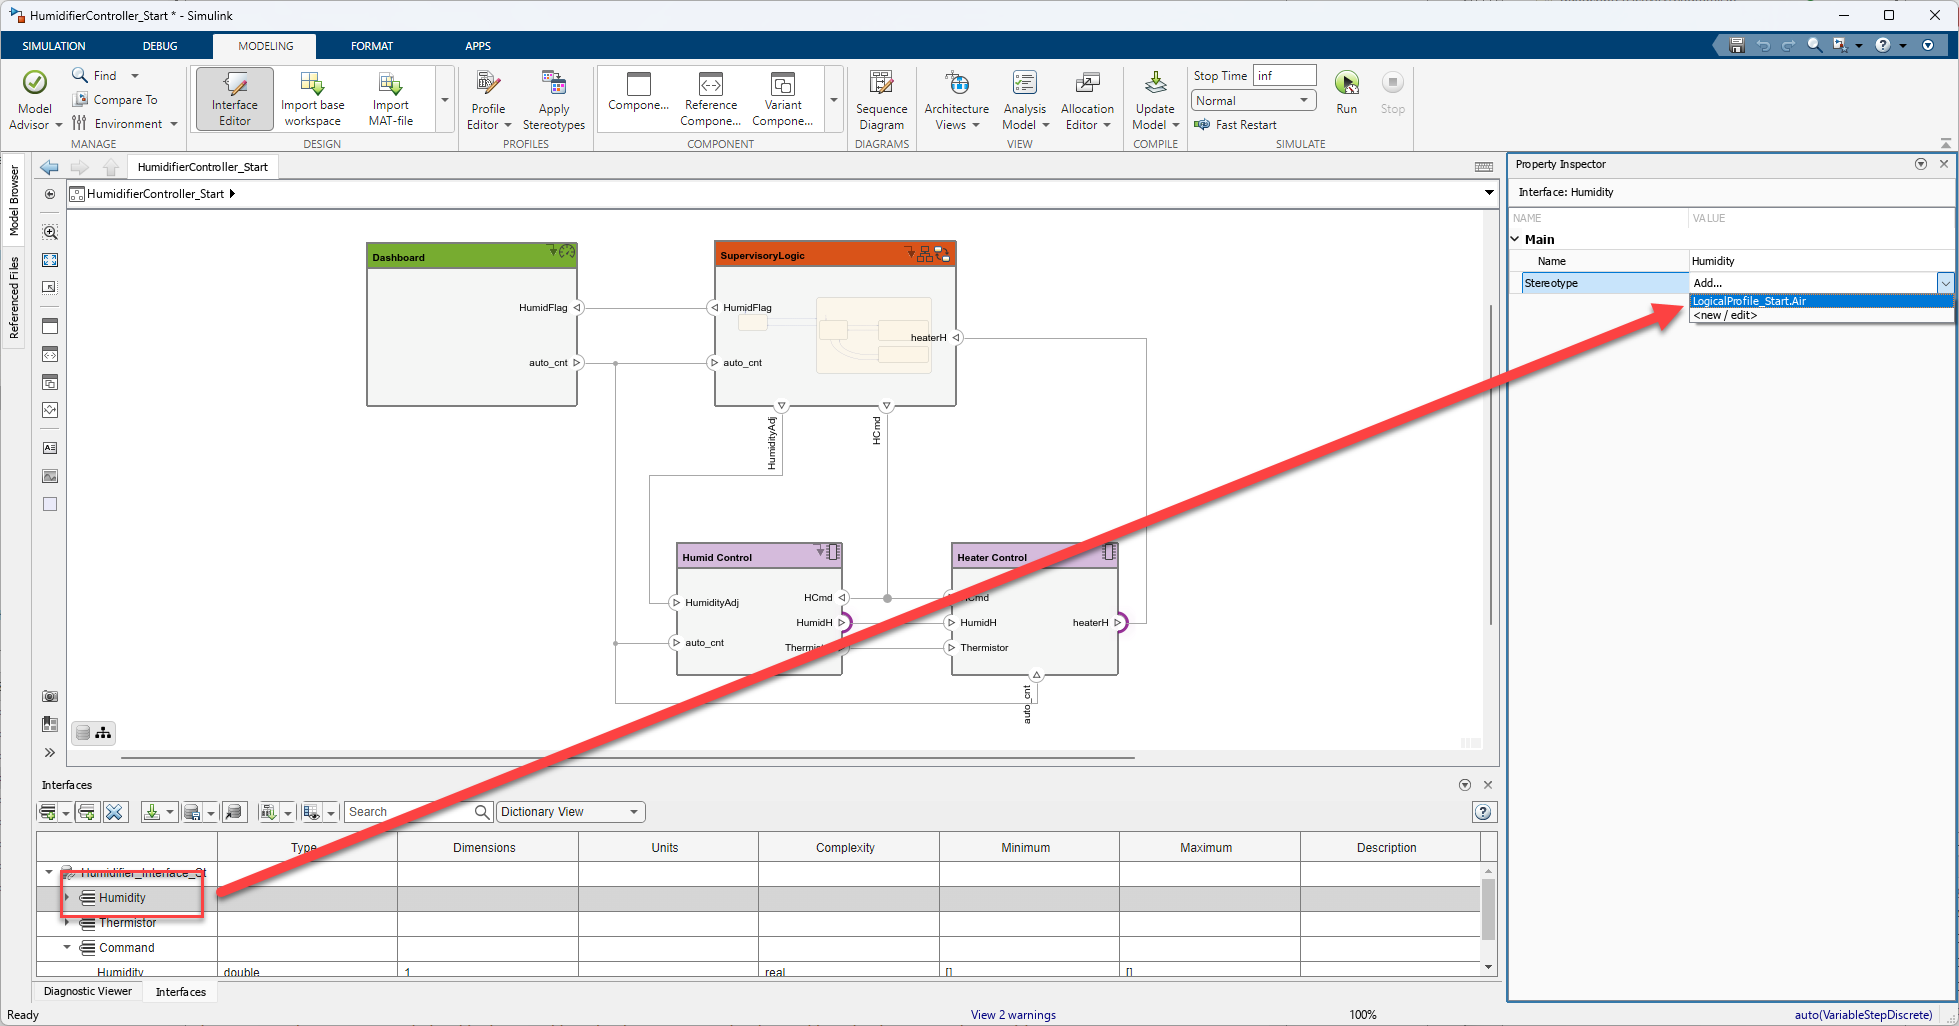

10). Save Logical architecture model and interface data dictionary.

#### 2.2.3 Building a Profile

You can extend your architecture model using profiles and stereotypes. Profiles are stored as xml files and contain collections of stereotypes that can be used to add metadata to your model elements. Stereotypes can have additional attributes associated with them such as styling information and user-specified properties.

1). To create a new profile or open existing one, press the Profile Editor button in the PROFILES section of the Modeling tab in the System Composer toolstrip.

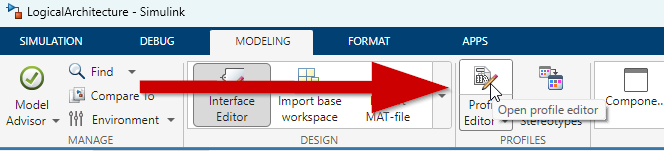

2). For this workshop, we have created one profile already. Please open 'LogicalProfile.xml' from "Working" directory. Review existing stereotype and properties of logical software components 

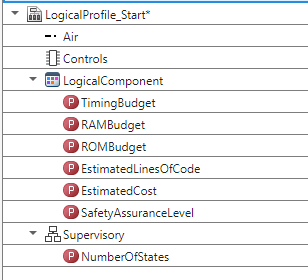

3). Add new stereotype named "Dashboard"

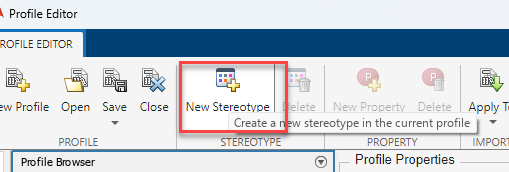

4). Select properties and add property names as shown below

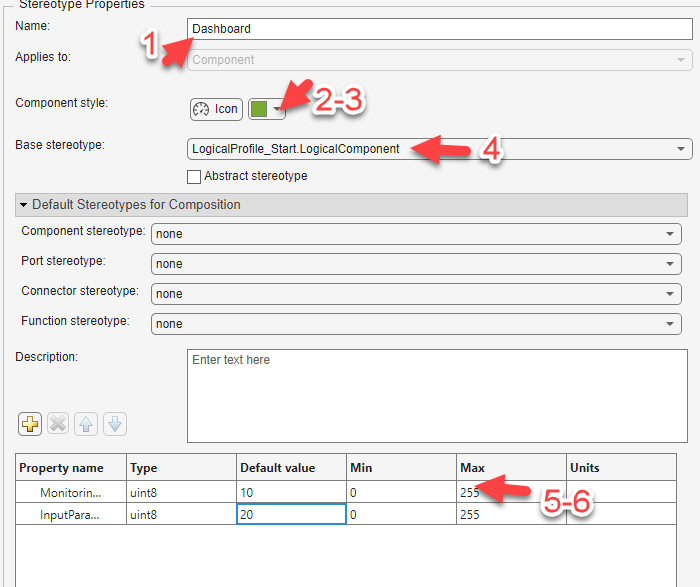

5). Now that the profile has been created, it can be associated with architecture models. Use the "Import into" drop-down to make the profile available for use in the logical architecture model "HumidifierController.slx".

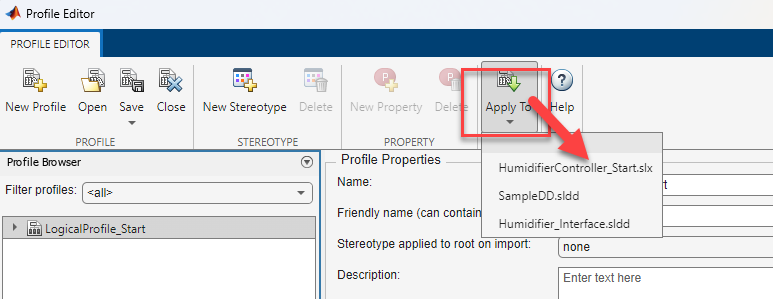

#### 2.2.4 Assigning Stereotypes

Stereotypes can be applied to the elements in the architecture model to "type" them with additional metadata. 

1). Select the Dashboard component and use the property inspector to apply the Dashboard stereotype as shown below. Also use approapriate stereotype for Supervisory and two control components as shown below.

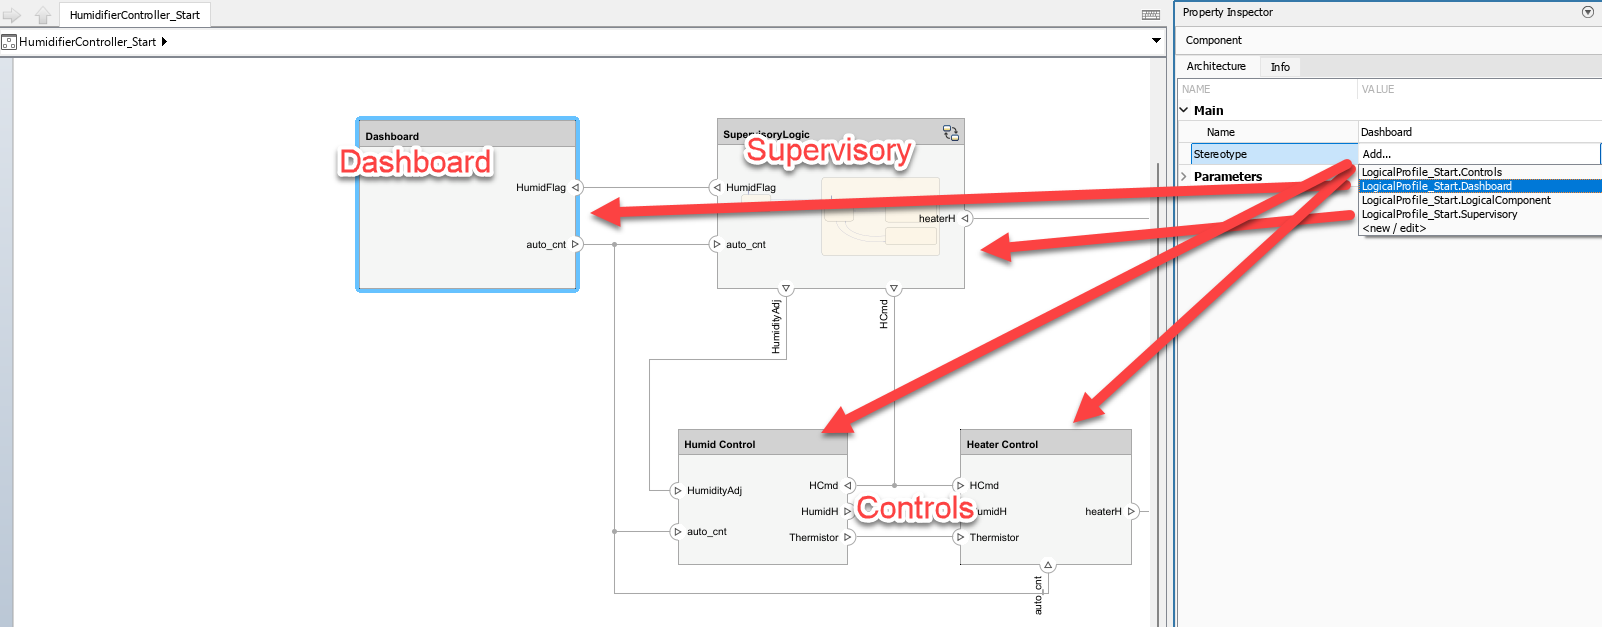

2). Change EstimatedCost for below components from property inspector as shown below.

- Dashboard - $25

- Supervisory - $2

- Humid Control - $5

- Heater Control - $7

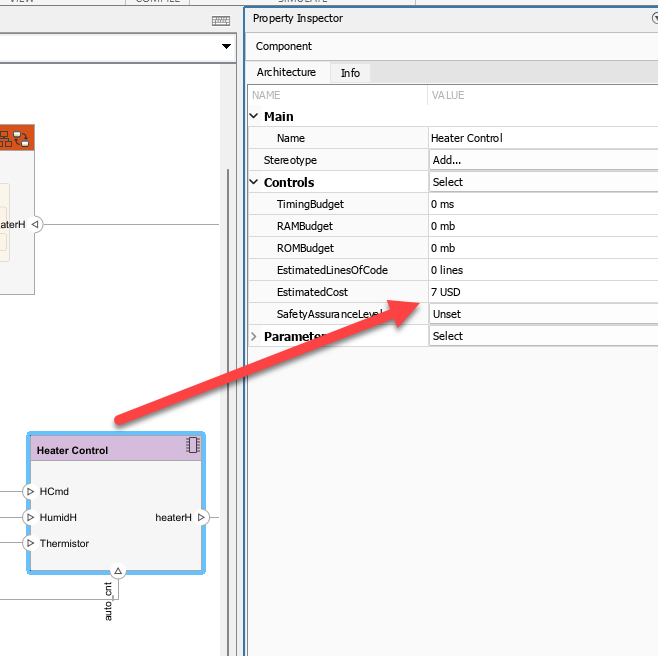

#### 2.2.5 Allocations

Multiple architecture models may be used to represent different abstractions of the same system. For example, a functional architecture, and a logical architecture. Allocations can be used to create a digital thread between these.

1). From System Composer, press the "Allocation Editor" button in the VIEWS section of the Modeling Tab

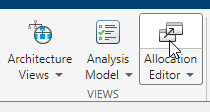

2). Press "New Allocation Set"

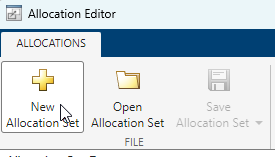

3). Name the new allocation set FunctionToLogical and choose the functional architecture as the allocation source and the logical architecture as the allocation target.

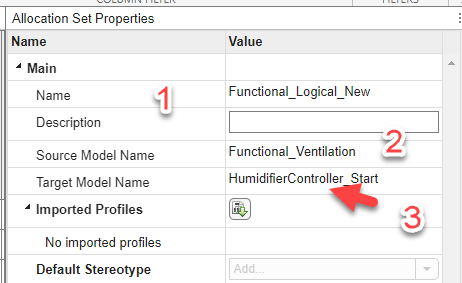

4). Create atleast 3 allocation from functional architecture to logical architecture components as shown below. SAVE allocation set.

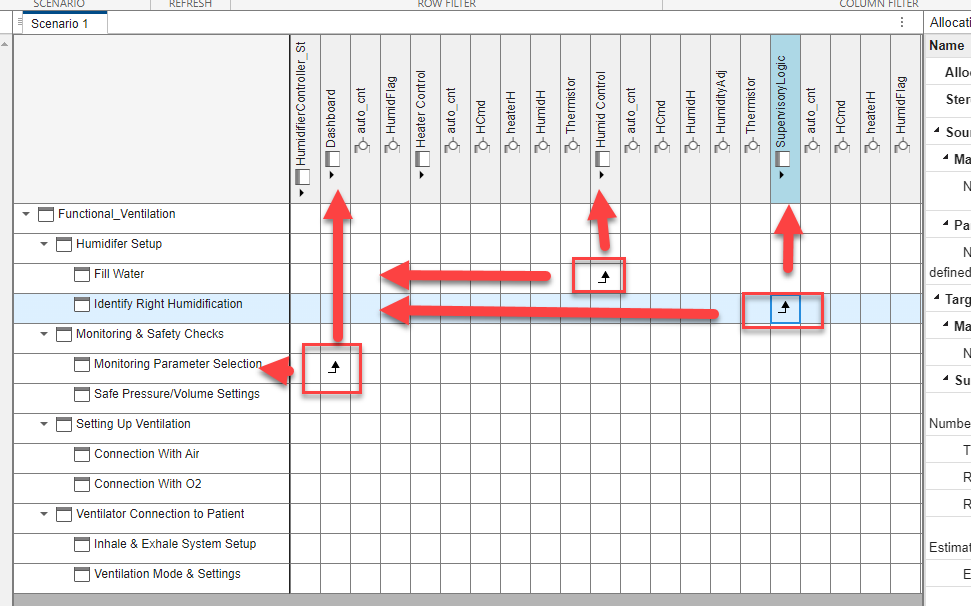

5). From Functional architecture model or logical architecture model, allocation can be seen and access as shown below.

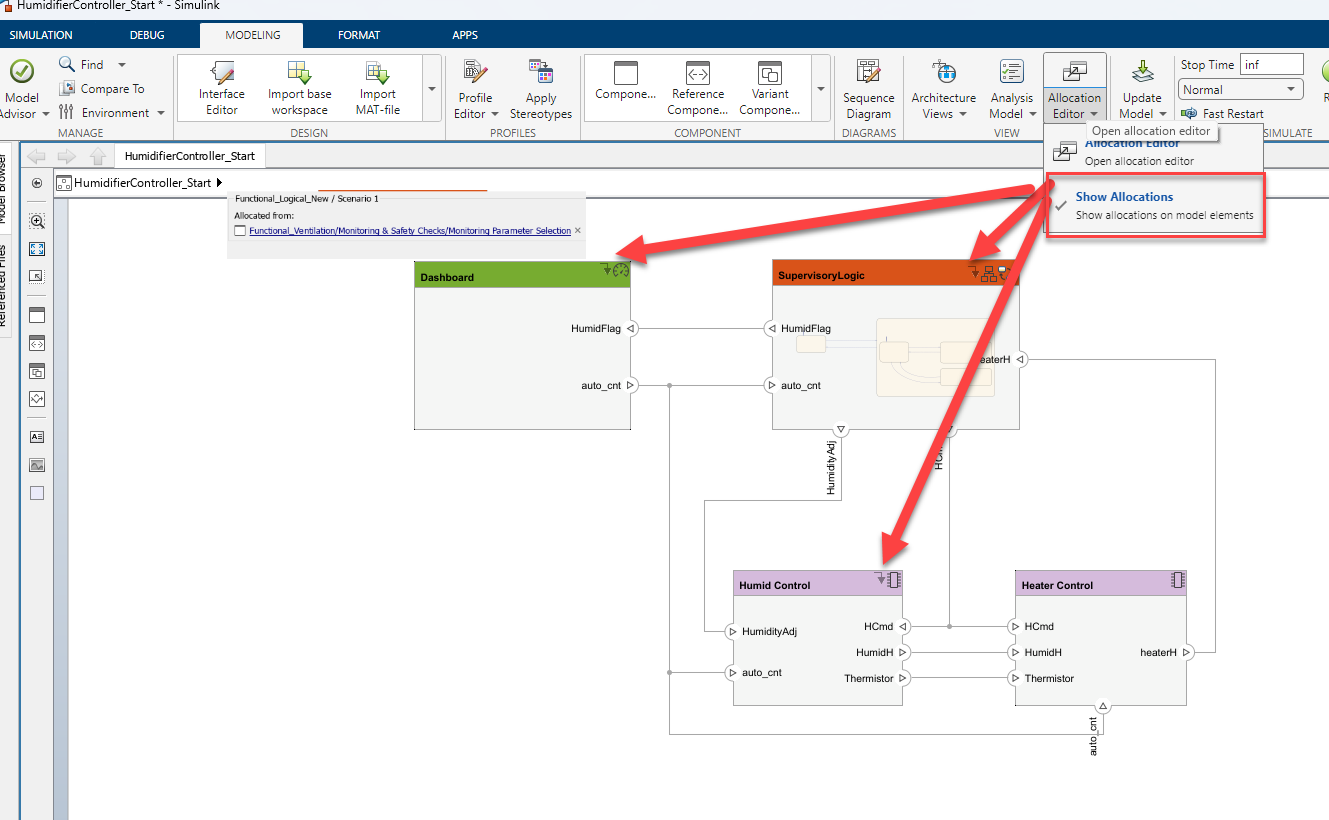

6). Save the [allocation set](matlab:systemcomposer.allocation.editor) and [functional](matlab:open_system('FunctionalArchitecture');) and [logical](matlab:open_system('LogicalArchitecture');) architectures.

#### 2.2.6 Simulink Integration

There are two main workflows for referencing Simulink models or other architectures: top-down or bottoms-up. In the top-down workflow, you right-click the component and choose "Save as Architecture" or "Create Simulink Behavior" (or other supported types). When you do that, the data dictionary will be linked to the newly-created skeleton model which can then be further decomposed. With bottom-up workflows you can instead link existing models to the components in your architecture. Architecture models can be linked in a similar way. In this workshop, we will use bottom-up workflow. 

1). Right-click the Humid Control component and choose "Link to..." --> "Model"

2). Select "Humid_Control.slx" subsystem reference model from "Working" directory.

3). Similiary link simulink behavior models Heater_Control to tHeater Control architecture components respectively as shown below. 

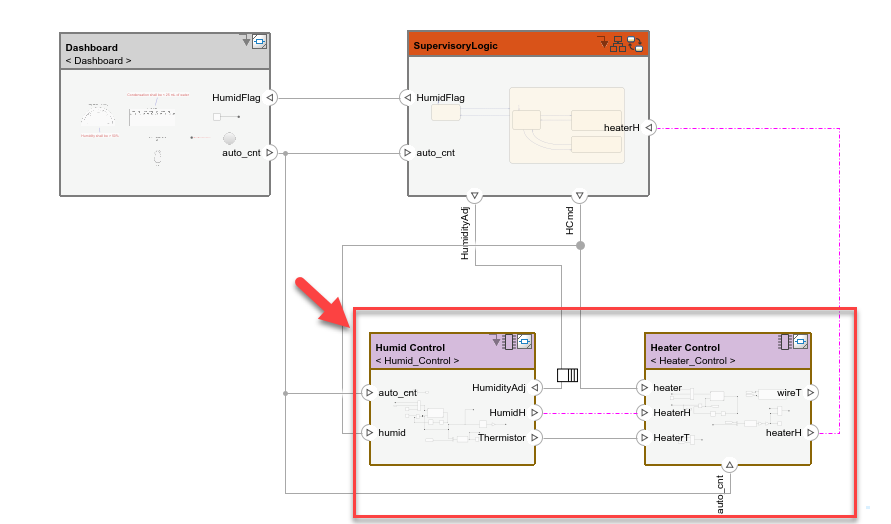

#### 2.2.7 Sequence Diagram Creation

Sequence diagrams can be used to describe intended interactions between existing architecture elements.

1). Open sequence diagram from system composer toolstrip

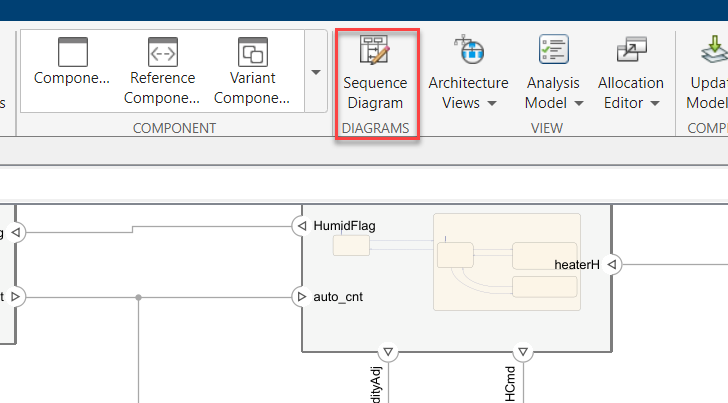

2). se the drop-down on the "New" button and select "Sequence Diagram" and name the diagram "Humidifier".

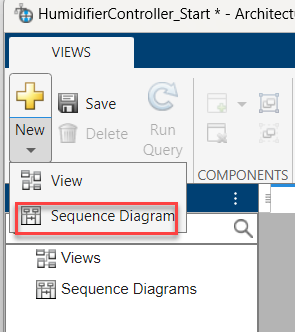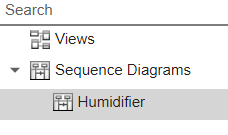

3). Components are represented in the sequence diagram as lifelines. One can add new lifeline or use existing one that they created during logical architecture building. Drag and drop all lifeline/component from 'Model Components' view.

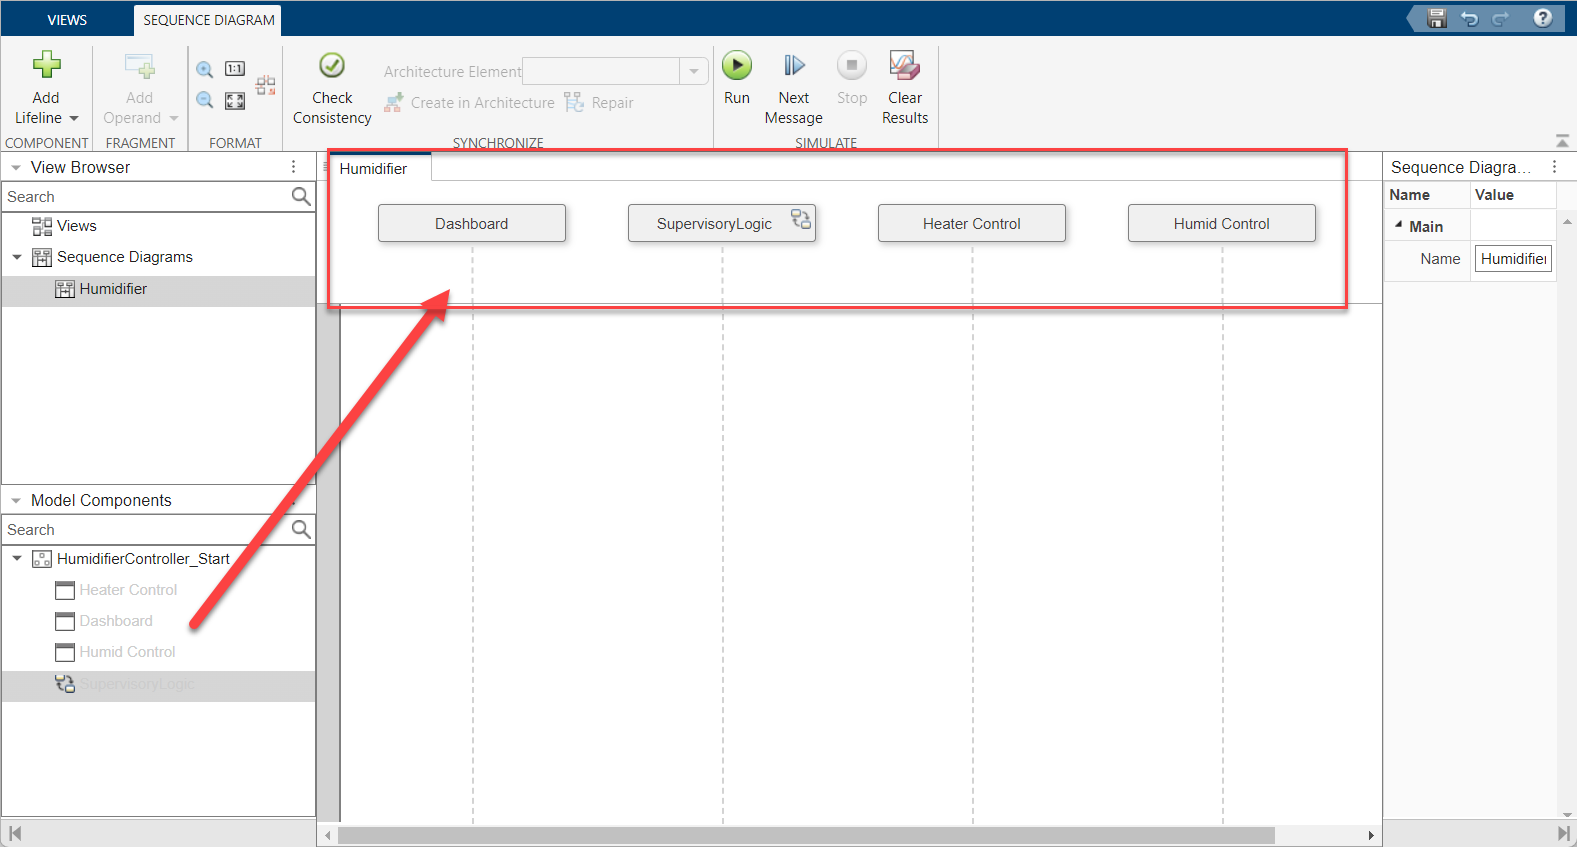

4). You can also add child components similar way as we added parent component in previous step. However, we don't have any child component for this logical architecture diagram.

5). Click and drage from the SuperviosryLogic to Dashboard lifeline. Select existing interface **HumidFlag** for 'To' and 'From'

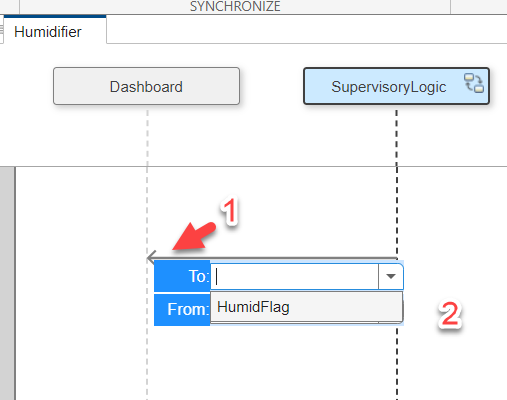

6). Create one more connection from SupervisoryLogic to Humid_Control, select existing message interface **HumidityAdj **for 'To' and 'From'

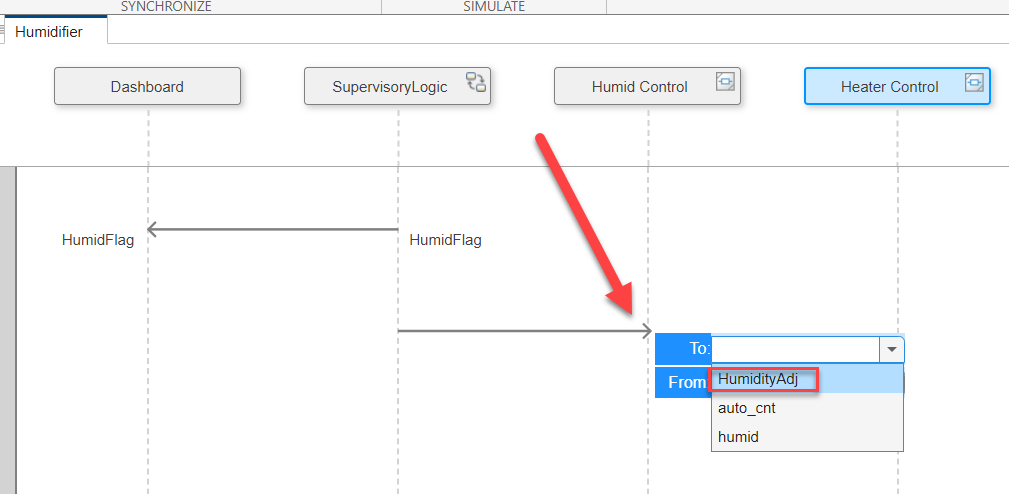

7). Now, lets add triggers to the connections. Sequence diagrams are event-driven and require a trigger condition to activate. A trigger can be a function call, a message, or a zero-crossing event (rising/falling/crossing). For the first trigger, add the 'rising' event for the HumidFlag. 

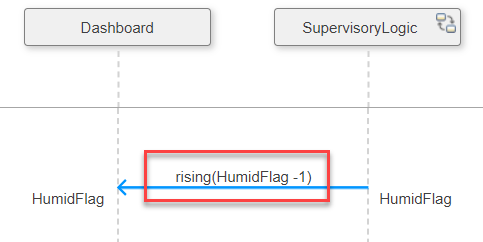

8). Add another trigger message for HumidityAdj flag as shown below. If the trigger should only fire under certain conditions, a constraint can be added to the connector in square brackets.

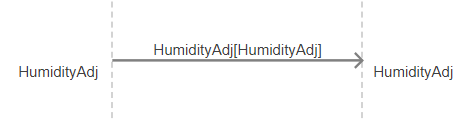

9). Check consistency and run simulation. Observe the response.

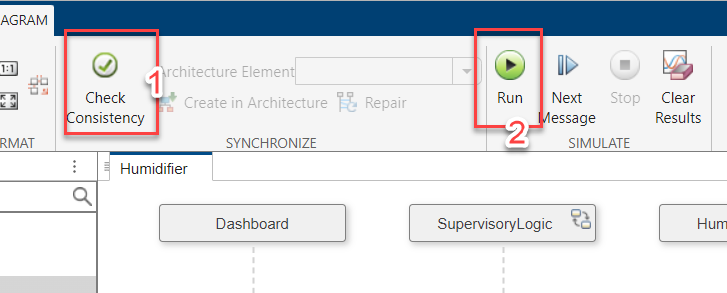

10). As both HumidFlag and HumidityAdj events are triggered after specific valid condition. We can add alternative fragment here. The alternative fragment models the classic *if-then-else* programming statement. More information on fragments can be found at the link below:

    [https://www.mathworks.com/help/systemcomposer/ug/sequence-diagram-fragments-for-message-ordering.html](https://www.mathworks.com/help/systemcomposer/ug/sequence-diagram-fragments-for-message-ordering.html)

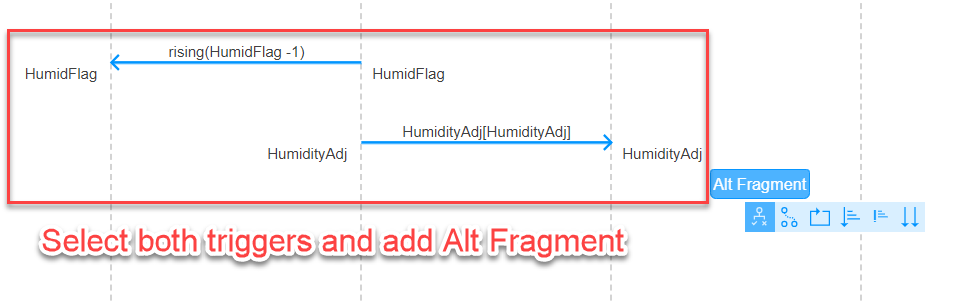

Add if condition auto_cnt == 1 as shown below. 

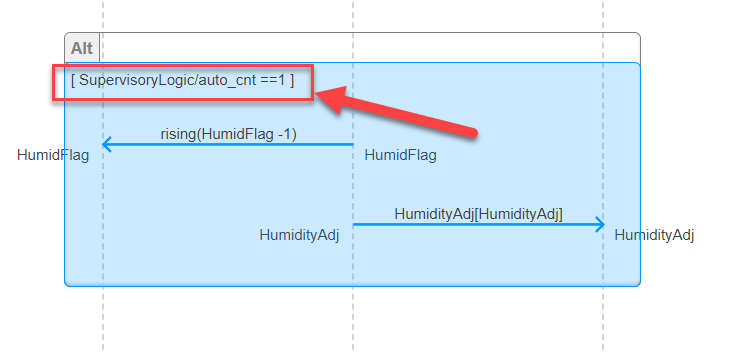

11). Add Else condition by clicking on 'Add Operand' --> Insert After. Add HumidFlag trigger and add event as falling event. This is because when auto tuning is turned OFF, HumidFlag should transition from true to false. 

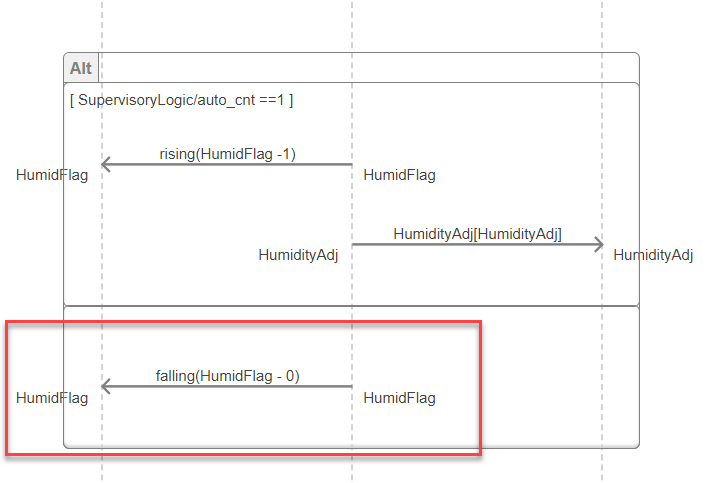

**Question: What if we want to continously monitor these Alt Fragment conditions, not just once check and done?  **

12). In case of looping certain part of the logic, use 'Loop' frangement. Single left-click the canvas to deselect everything. Drag and select Alt condition and create loop fragment as shown below. This creates expected behavior such as logic should continously look for 'auto_cnt' switch even and set 'HumidFlag' accrodingly. 

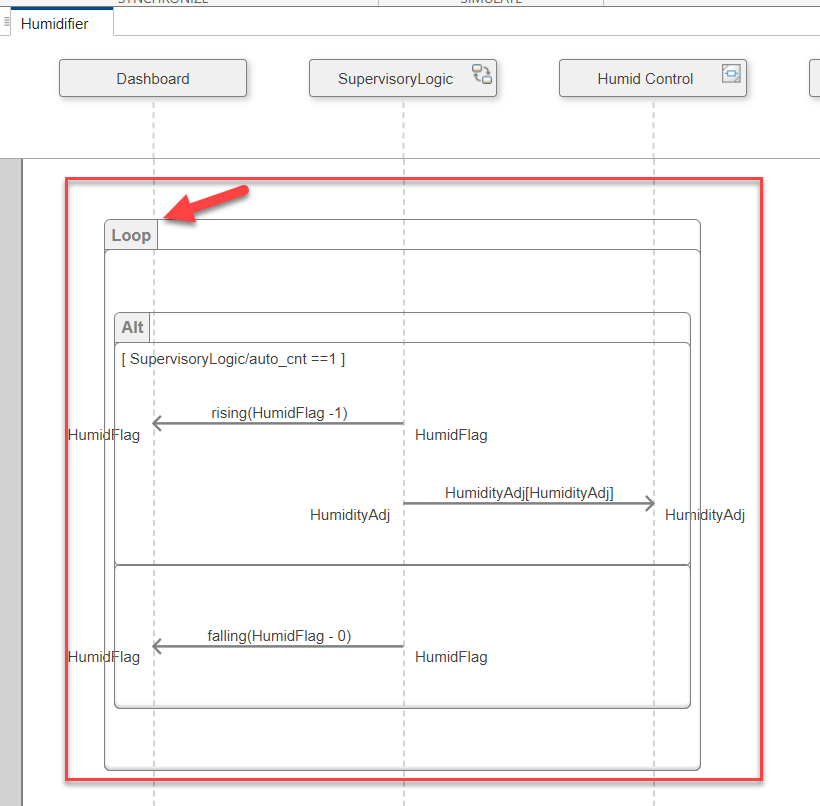

13). Save and rerun the model from sequence diagram tab. From 'Dashboard' subsystem, turn ON and OFF autoTuning switch and observe how we can implement some abstract logic in sequence diagram and validate using Simulink/Stateflow behavior diagrams. 

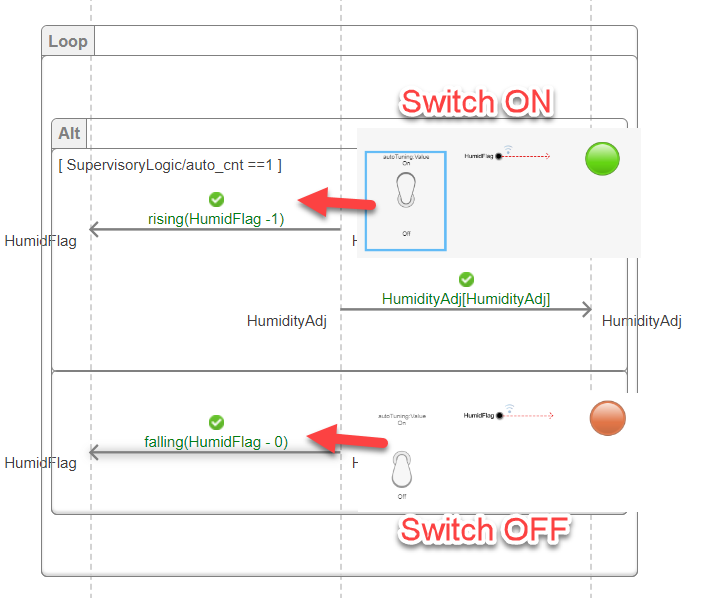

14). Close the Architecture Views Gallery and save the logical architecture.

#### 2.2.8. Dataflow analysis

As a systems engineer, it is a common task to study the flow of data across an architecture. System Composer helps you trace signals through both you architectural (System Composer) and behavioral (Simulink) models.

1). To start a data trace, right-click a connector and choose "Highlight Signal to Destination". The auto_cnt data will be used for this example. Use the right and left arrow keys on the keyboard to trace the signal to its source or destination and understand how it propagates across the system.

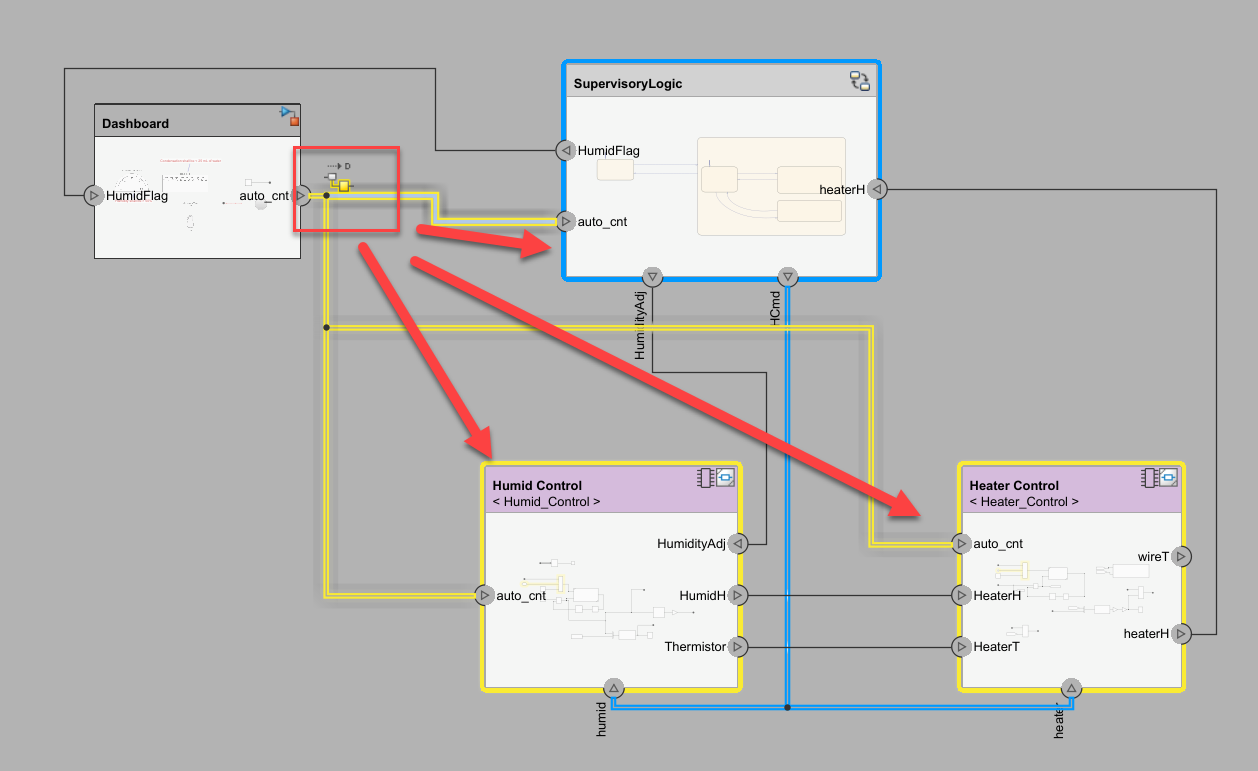

2). When you are finished, press the X in the top-right of the main viewer to exit the tracing view.

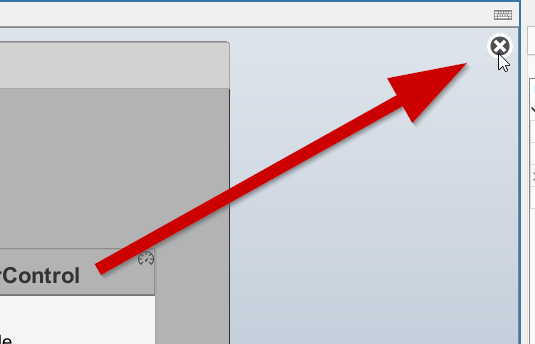

### 2.3 Architecture View & Analysis

We will use prebuilt physical architecture, explore different ways to visualize the architecture, add variant choices to some of the physical components, and finally perform a trade study using the analysis iterator. 

Copy files from **ArchitectureDiag/TradeStudy** folder and **CostAndWeightRollupAnalysis.m** file to the **Working** directory or press[** Do it for Me!**](matlab:cp = currentProject;  cd(cp.RootFolder); status =rmdir('Working','s');mkdir 'Working';copyfile("ArchitectureDiag/TradeStudy/","Working");copyfile("Scripts/CostAndWeightRollupAnalysis.m","Working");cd Working/;)  

#### **2.3.1 Views**

In this section, we will use the Architecture Views Gallery to visualize the topology of our ventilator system.

1). Open the Architecture Views gallery in the [Logical architecture](matlab:open_system('Logical_Ventilation');).

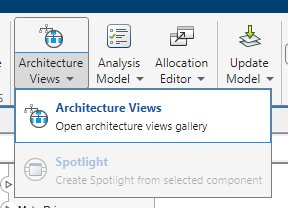

2). Open the pre-built 'Ventilator' view. This is a query-based filter view. The existing query can be seen in the View Configurations pane at the bottom.

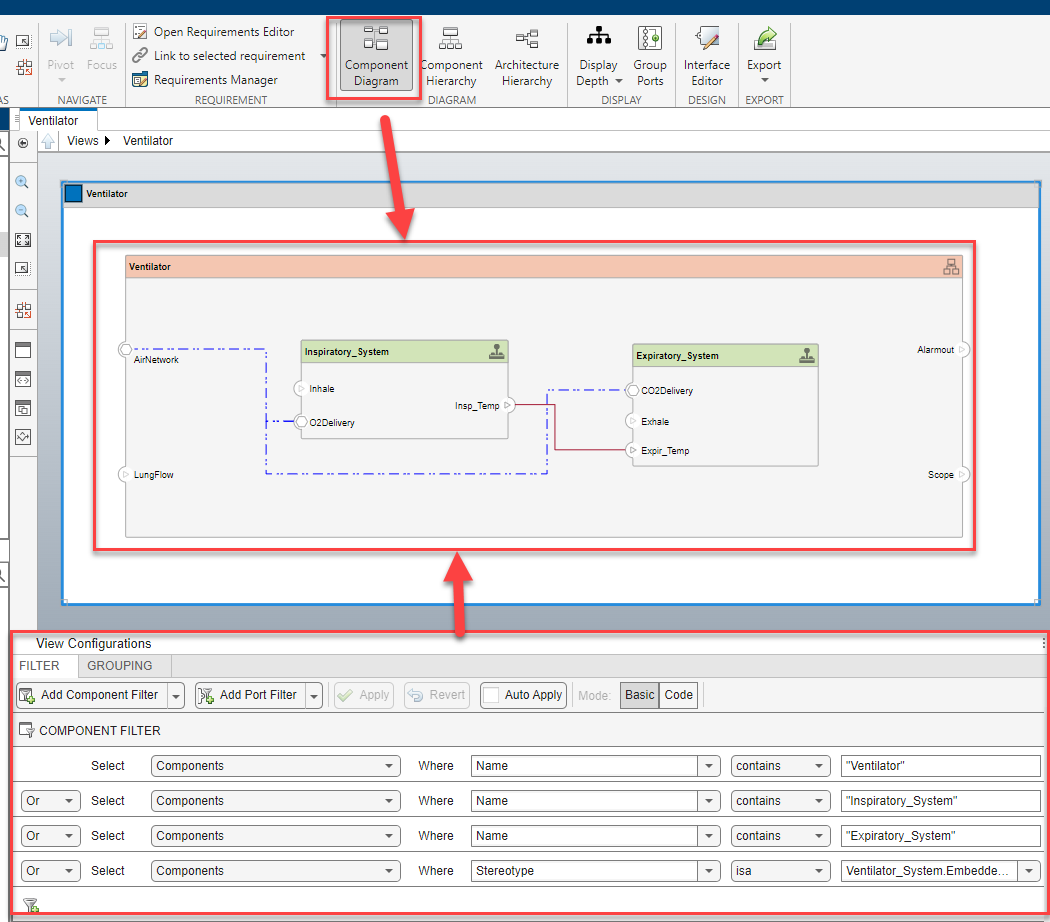

3). Besides component filters, you can also add port filters to further refine the view. 

#### 2.3.2 Variant Components

Ventilator flow sensors come in several types. Ventilator flow sensors can be either proximal or distal, with proximal sensors located closer to the patient's airway and distal sensors closer to the ventilator outlet. Proximal sensors offer more accurate and responsive readings, especially for detecting leaks and the beginning of inspiratory efforts, while distal sensors primarily measure the ventilator's output. We need to add them both as variants and then use the analysis iterator in System Composer to choose the optimal part. 

1). Open the Ventilator component from logical ventilator architecture model. 

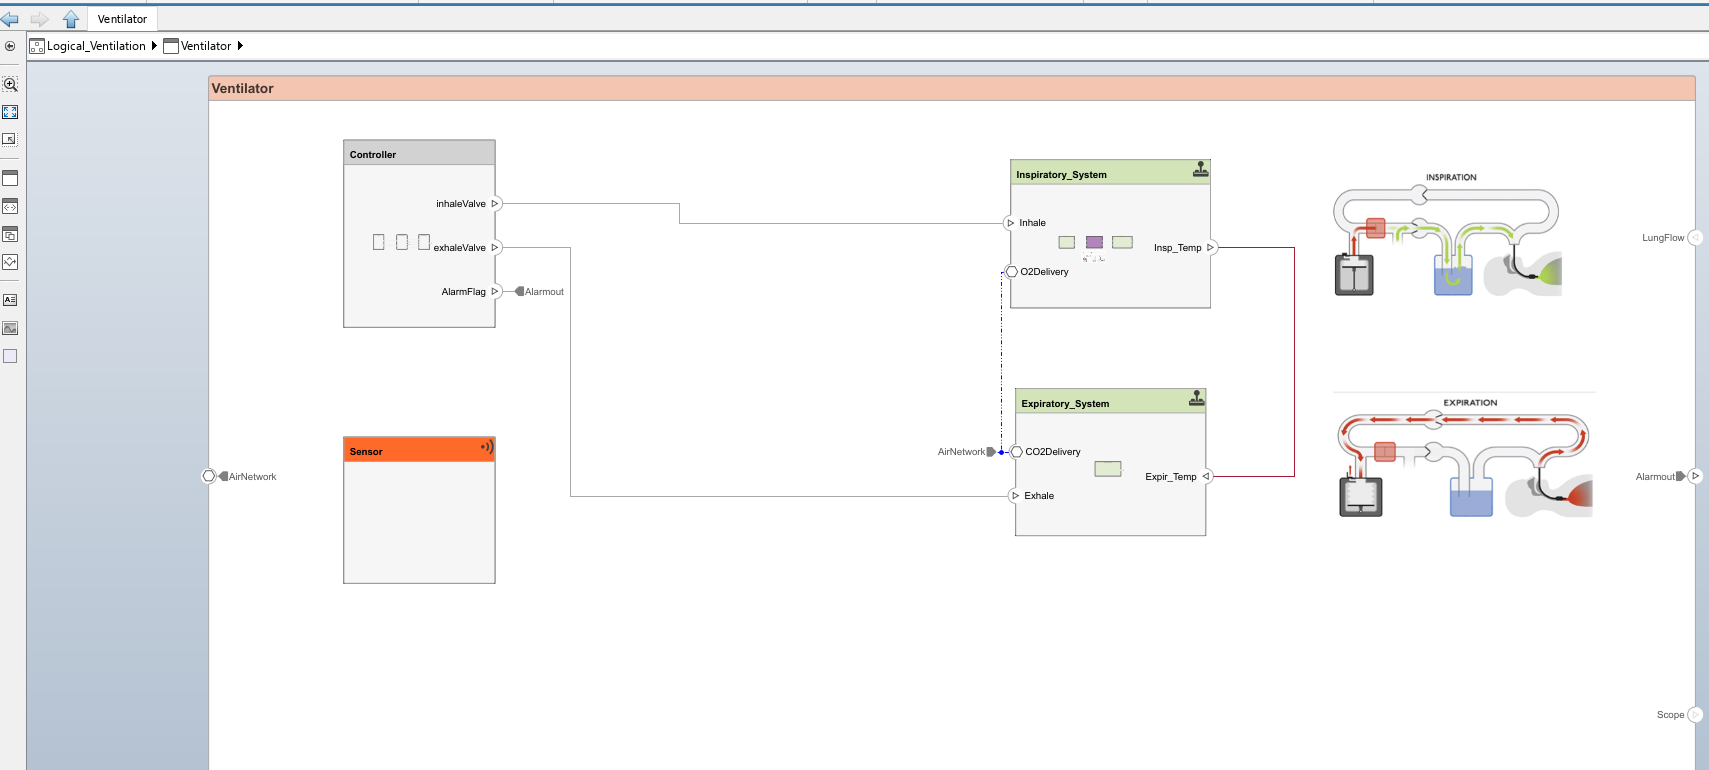

2). Right click on Sensor component and select 'Add Variant Choice'. Change Variant control model to --> label. This will add variant for the Sensor component. Give two different names to these variants such as "Proximal Sensor" and "Distal Sensor". 

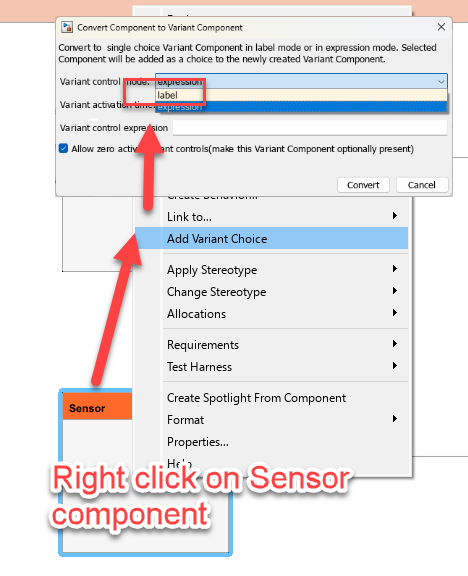

3). Assign the stereotype Ventilator_System.Sensor to Distal sensor. Change cost, weight and ComplianceSafetyLevel of these two sensor variants as shown below. 

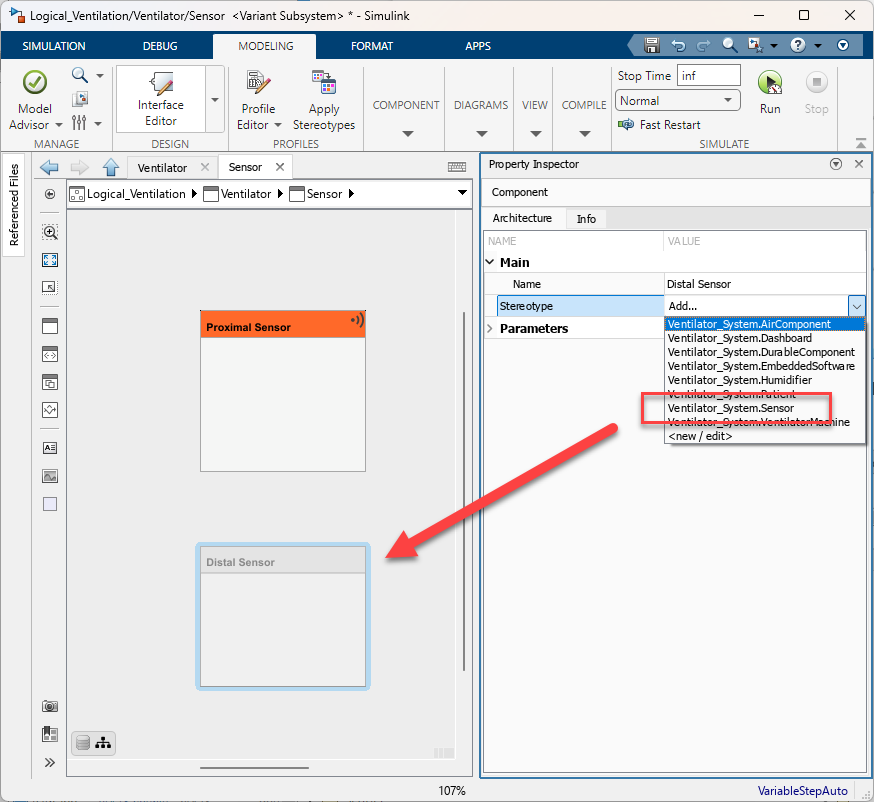

    **Sensor**                            `Proximal Sensor`            `Distal Sensor`

    **UnitCost**                                   $50                          $75

    **Weight**                                      35 grams                15 grams

    **ComplianceSafetyLevel**          Moderate                 Moderate

  4). Make sure Proximal Sensor variant is selected.. Variant choices can be changed by right click on the component. Example: 'Sensor' component --> Label Mode Active Choice --> Proximal Sensor

#### *2.3.3 Analysis*

We will now conduct a bottom-up analysis to determine which flow sensor to choose. Conducting a bottom-up analysis will result in the lowest-level components (and/or interfaces, ports, and connectors) being passed to the analysis function first and then the next level up and so on until reaching the top of the architecture tree. This means that the analysis function is called once for each component passed to it. It also make conducting roll-ups easy because rather than writing a recursive loop, we only have to write a simple For loop to check the next-lowest level when we encounter a parent component and the analysis iterator will handle the rest of the recursion for us.

1). Select "Analysis Model" on the ribbon (Modeling tab, VIEWS section) of the Logical_Ventilation.slx architecture model

2). Select **'DurableComponent' **stereotype for the analysis (contains cost/mass/power/accuracy/compliancelevel etc), specify **Strict Mode** to only include components with that stereotype assigned, set the iteration order to **Bottom-up.**

3). Type the name of the included analysis function, "CostAndWeightRollupAnalysis" [(click to view)](matlab:open('CostAndWeightRollupAnalysis')). This function gets called iteratively by the Analysis tool. Each time it is called, a new component is passed to it according to the specified iteration order.

4). After specifying the analysis function, press the Instantiate button.

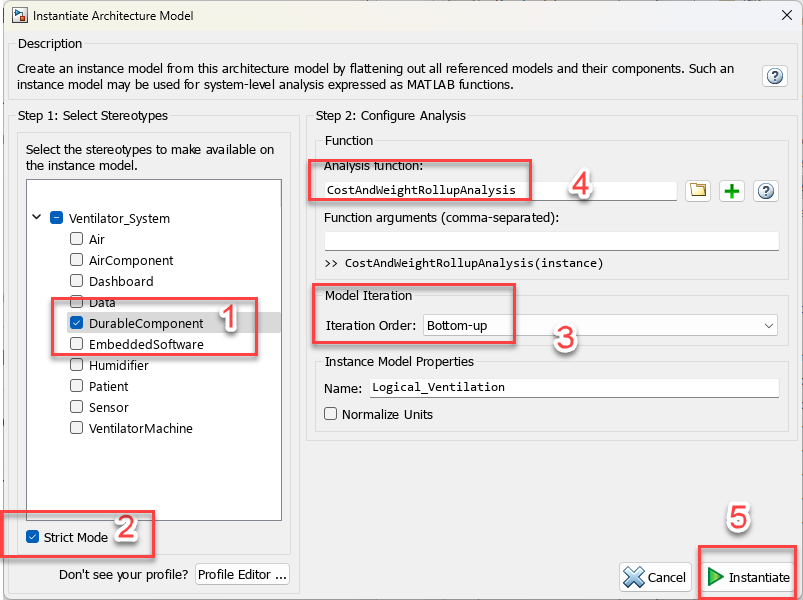

The Analysis Viewer opens and displays the current stereotype property values. Notice how the parent properties were intentionally left blank by the systems engineer when the stereotypes were assigned. Any changes made programmatically or manually in the analysis viewer will NOT update in the model unless you press the "Update" button. This analysis instance is just an instantiation of the model, not the actual model. Likewise, if changes are made to the model, it is necessary to press the "Refresh" button to pull those changes into the Analysis Viewer.

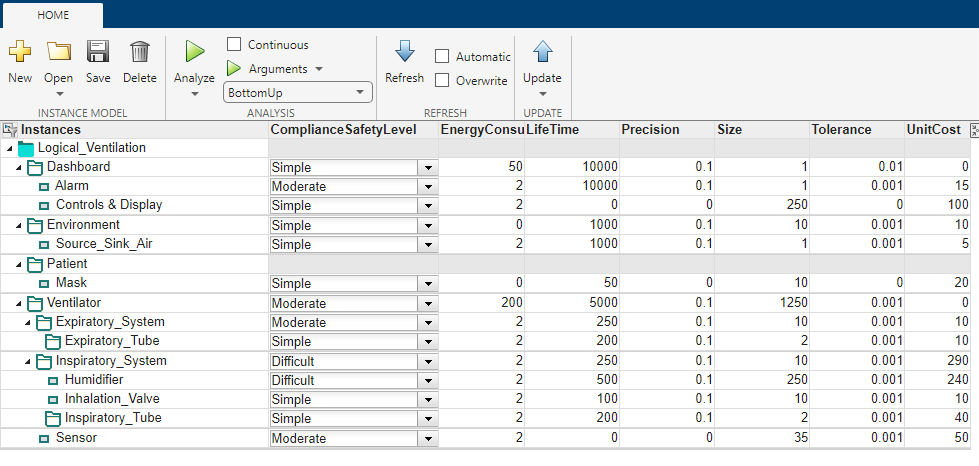

5). ress the Analyze button to run the analysis function.

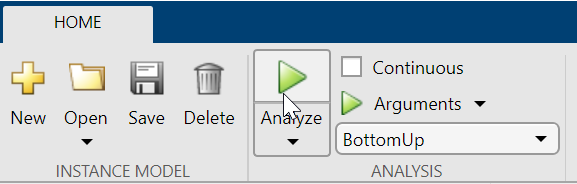

6). Observe that a full roll-up has been conducted:

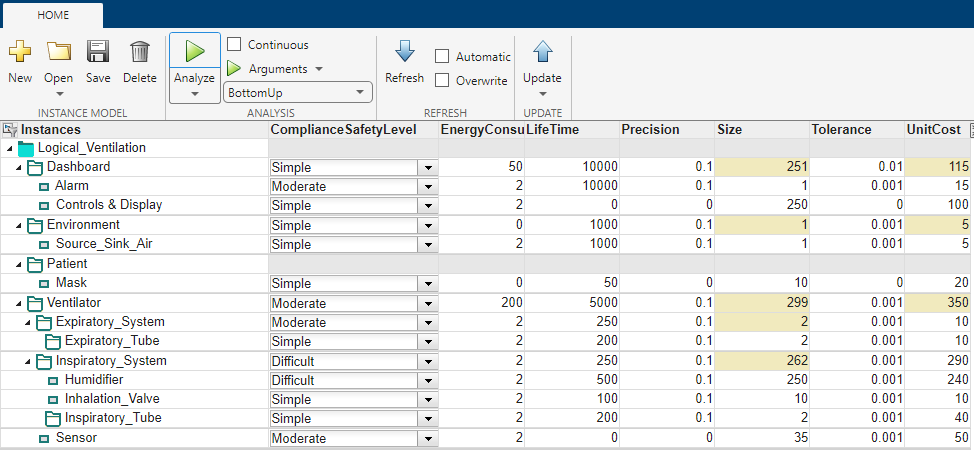

7). Save this instance model and analysis results as Rollup1.mat in the working directory.

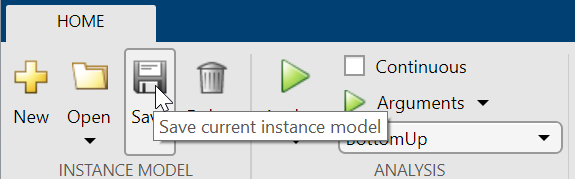

8). Close this analysis and change the variant in the 'Sensor' to the other 'Distal Sensor'.

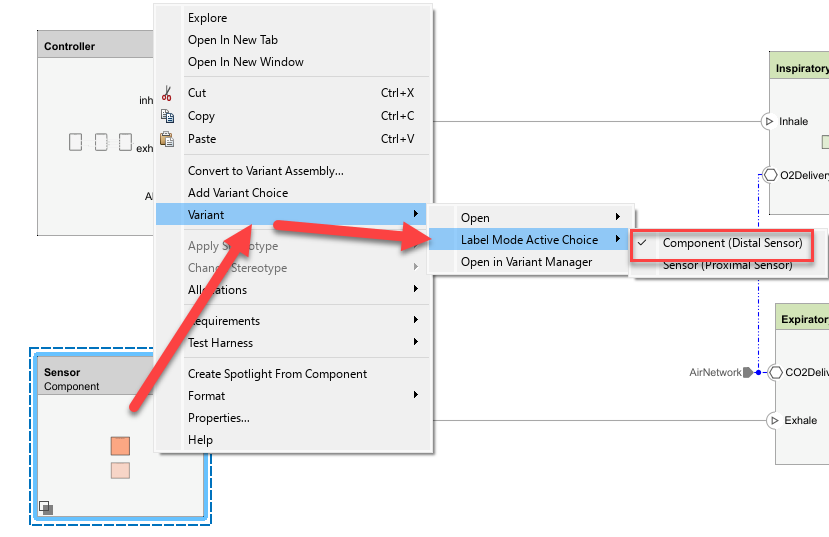

9). Follow again step 1-6 to perform analysis using sensor variant (distal sensor) this time. Overwrite the existing analysis (it's okay, we saved previous Proximal Sensor analysis for reference later).

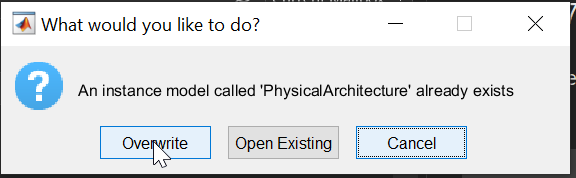

10). Press the Analyze button and observe that the analysis has been updated with the new results. 

                                     **Variant                          Cost            Mass       **

**Previous Roll-Up:**      Proximal Sensor            350                299                       

  **      New Roll-Up: **     Distal Sensor                 375                279                     

The analysis has shown us that Proximal sensor adds some weight to overall ventilator machine but cost wise it's slightly cheaper than Distal sensor.. Here we can more properties such as accuracy of the sensor, effort to calibrate/tune, life expectance of the sensor and many more. With all data combine, one can perform informed analysis and come up with design choices during early phase of the system development. 

## 3.0 Reporting

### *3.1 Architecture Diagrams as Webview*

Now that all of these artifacts have been created in System Composer and Requirements Toolbox, there may be a need to just share an architecture diagram with a colleague, in that case you may wan to consider Webview option. One can use simulink report generator to generate detailed report which is not included in this workshop.

1). Open the Logical_Ventilation.slx file, go to the SIMULATION tab and press Save and select Web View...

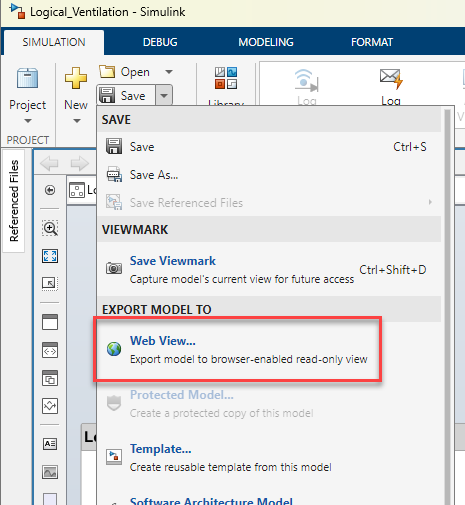

2). The Web view GUI has the option to package the web view as a zip file, unzipped or both. Select the option unzipped.

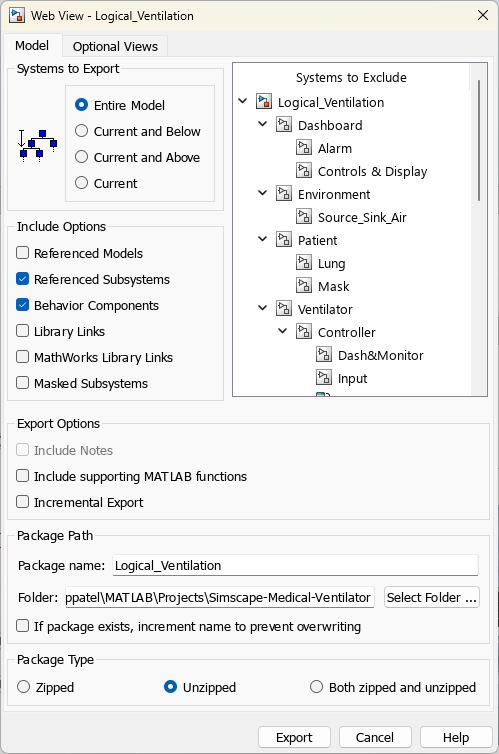

3). The Web view GUI has multiple self-explanatory options for what to export. We will choose for Entire Model, and Package Type Unzipped.

There are additonal items such as requirementslinks which can also be included in the report.

4). Select "Working" directory for package path and Press the Export button, close the web browser will be opened after the export.

5). Open webview.htlm from the Logical_Ventilation directory within "Working" directory in your project and observe how the output starts at the top-level and then breaks down into each subsystem recursively. Also relevant data such as interfaces and stereotypes can be displayed in the exported Architecture model.

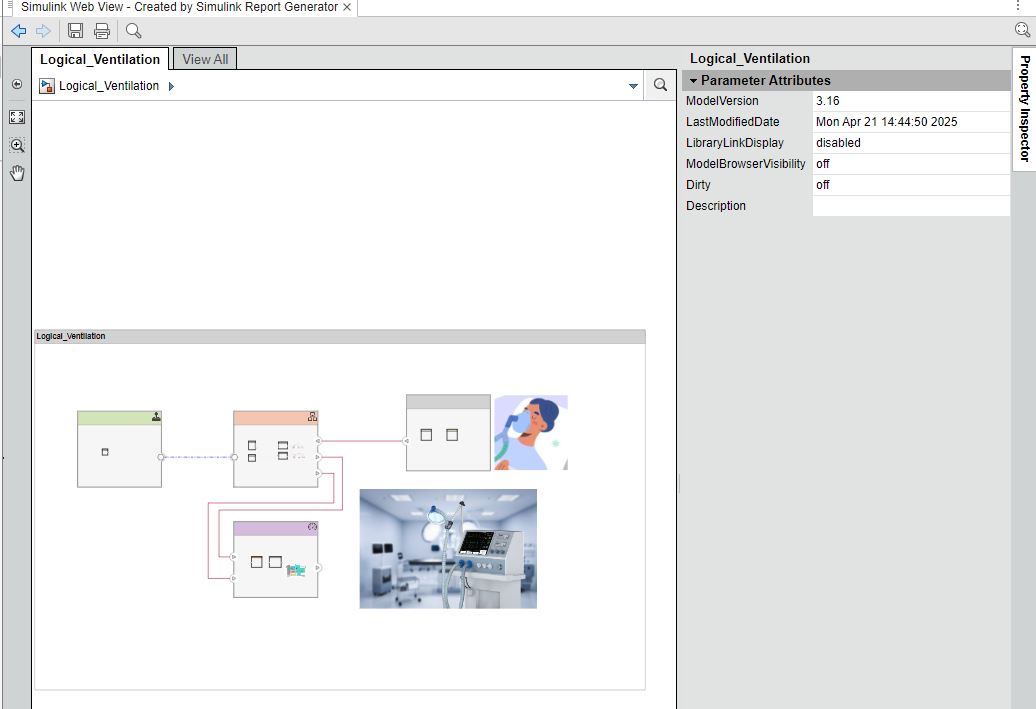

### ***3.2 Architecture Data (optional)***

Data associated with the architecture such as components, connections, port interface data, stereotypes and property values, can be exported via an API to System Composer. The following lines of code export the FunctionalArchitecture to the MATLAB workspace and then save that data to a Microsoft Excel file, FunctionalArchitecture.xls.


exportedSet = systemcomposer.exportModel("Working/Logical_Ventilation.slx");

SaveToExcel('LogicalVentilation',exportedSet);

The exported set has the following tables which become individual sheets in Microsoft Excel.

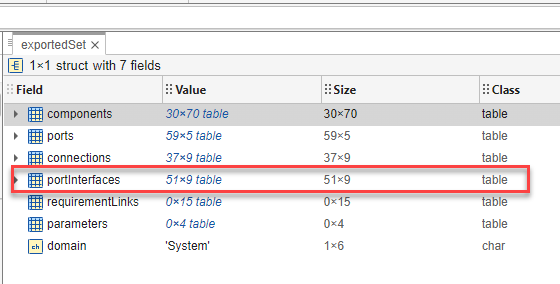

It is possible to save them individually also using MATLAB's writetable command. The following code example will save :

%writetable(exportedSet.portInterfaces, "FunctionalArchitecture_Interfaces.xls")

Error using systemcomposer.internal.isSystemComposerModel
Model 'Working/Logical_Ventilation.slx'.slx cannot be found on the MATLAB path.

Error in systemcomposer.internal.exportModelClass/runValidationChecks

Error in systemcomposer.internal.exportModelClass

Error in systemcomposer.exportModel

### *3.3 Requirements Export (optional)*

Reports for requirements can be created from the requirements editor.

1). Open the 2_SystemRequirements.slreqx

2). Press the Export button and then choose option "Generate Report"

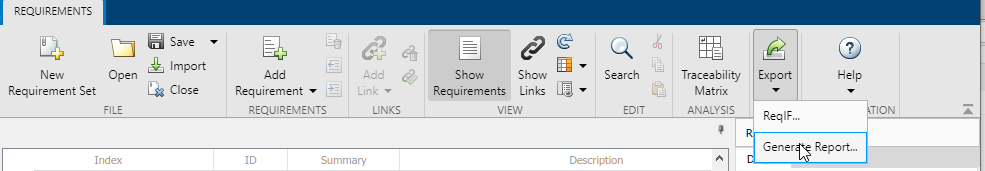

3). Specify the desired options then press Generate Report.

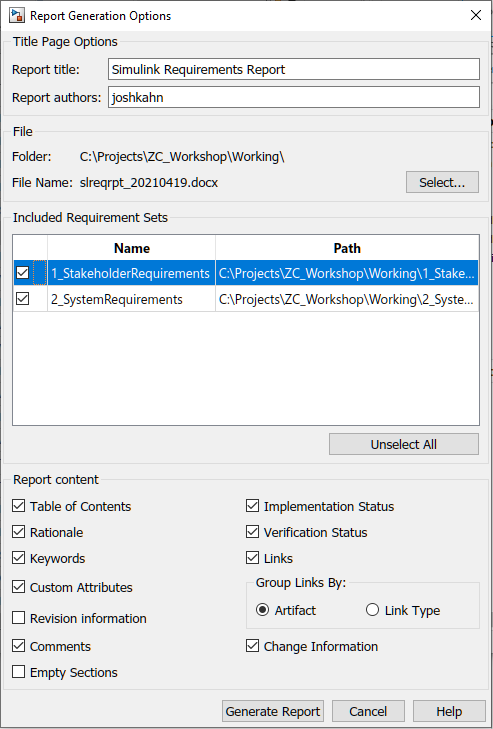

4). The report has now been output to slreqrpt_YYYYMMDD.docx

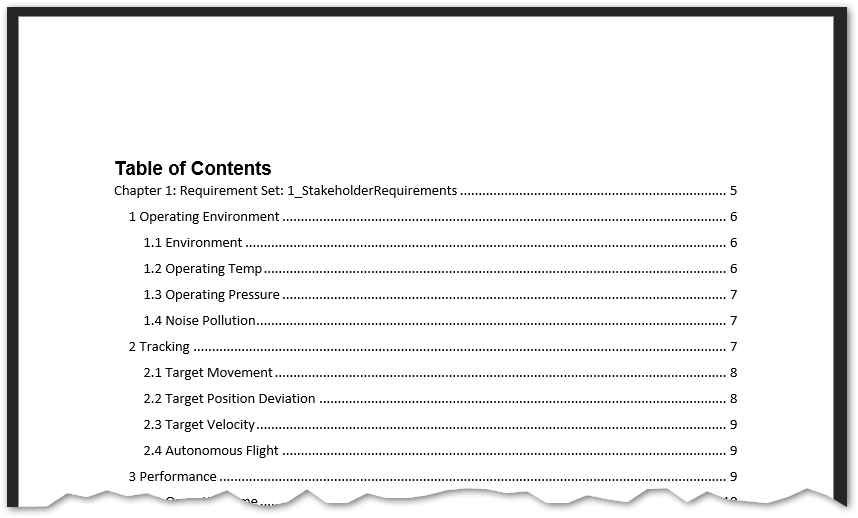

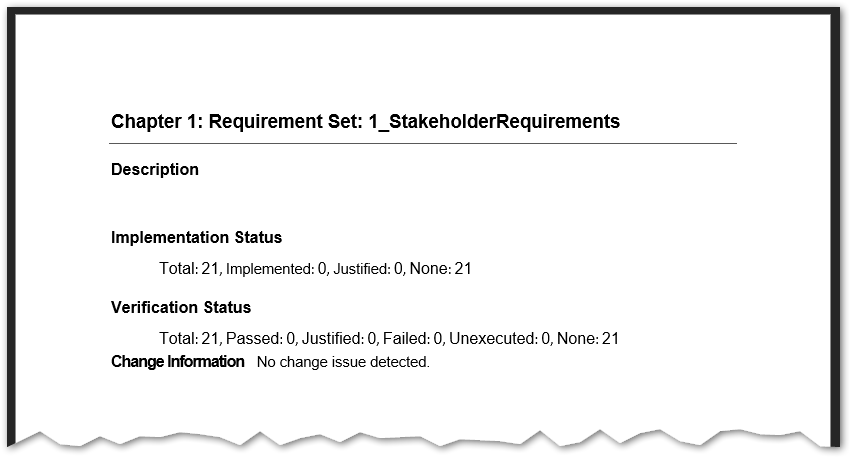

## 4.0 Conclusion

Thank you for taking the time to go through this workshop with us! This workshop has demonstrated use of System Composer as a System Engineering tool to create various types of diagrams, link with requirements and models, add properties to model components, allocate to other diagrams, perform variant analyses, and export the data for delivery to the customer or suppliers. Please let us know any feedback to help improve future iterations. 

Due to time constraints of this workshop, not all features could be explored. Some of the functionality not covered but available includes: 

### ***4.1 Simulating Architecture Behavior through System Composer***

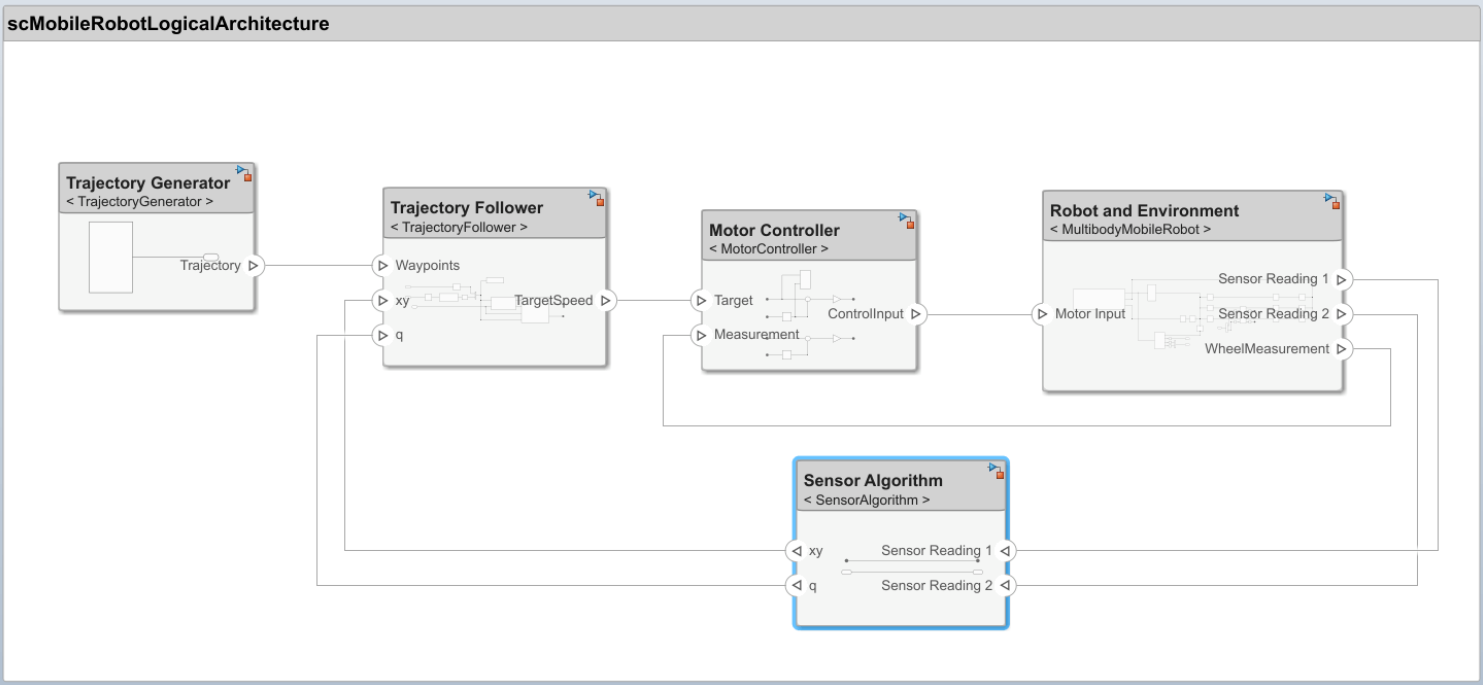

[https://www.mathworks.com/help/systemcomposer/ug/mobile-robot-workflow.html](https://www.mathworks.com/help/systemcomposer/ug/mobile-robot-workflow.html)

### ***4.2 Requirements-Based Testing***

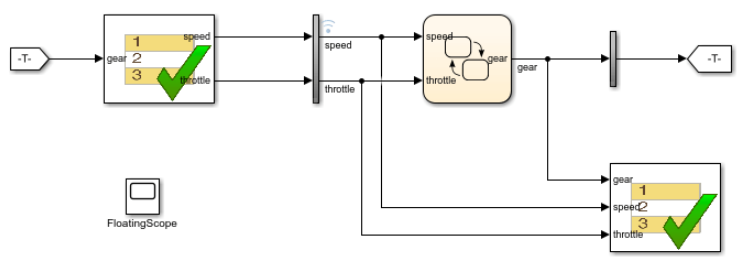

[https://www.mathworks.com/help/slrequirements/requirements-based-verification.html](https://www.mathworks.com/help/slrequirements/requirements-based-verification.html)

### ***4.3 Constructing Software Architectures***

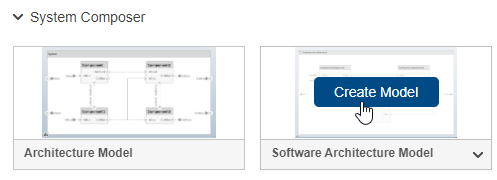

[https://www.mathworks.com/help/systemcomposer/ug/author-software-architectures.html](https://www.mathworks.com/help/systemcomposer/ug/author-software-architectures.html)